## Design Via Root Locus

### Improving Steady State Response

### Compensator Design

#### Ideal Integral Compensation

    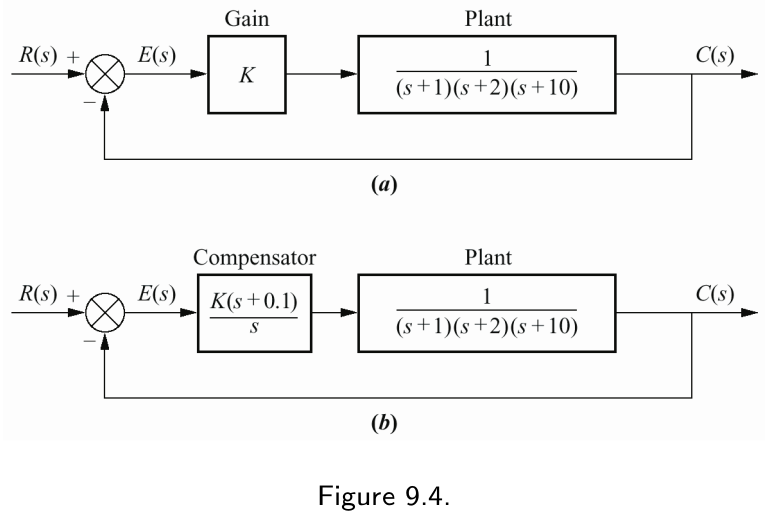

G=zpk([],[-1 -2 -10],1)

G =
 
          1
  ------------------
  (s+1) (s+2) (s+10)
 
Continuous-time zero/pole/gain model.



rlocus(G)
zeta=0.174

zeta = 0.1740

sgrid(zeta,0)
hold

Current plot held


s_1=-0.694+j*3.926

s_1 = -0.6940 + 3.9260i

evalfr(G,s_1)

ans = -0.0061 + 0.0000i

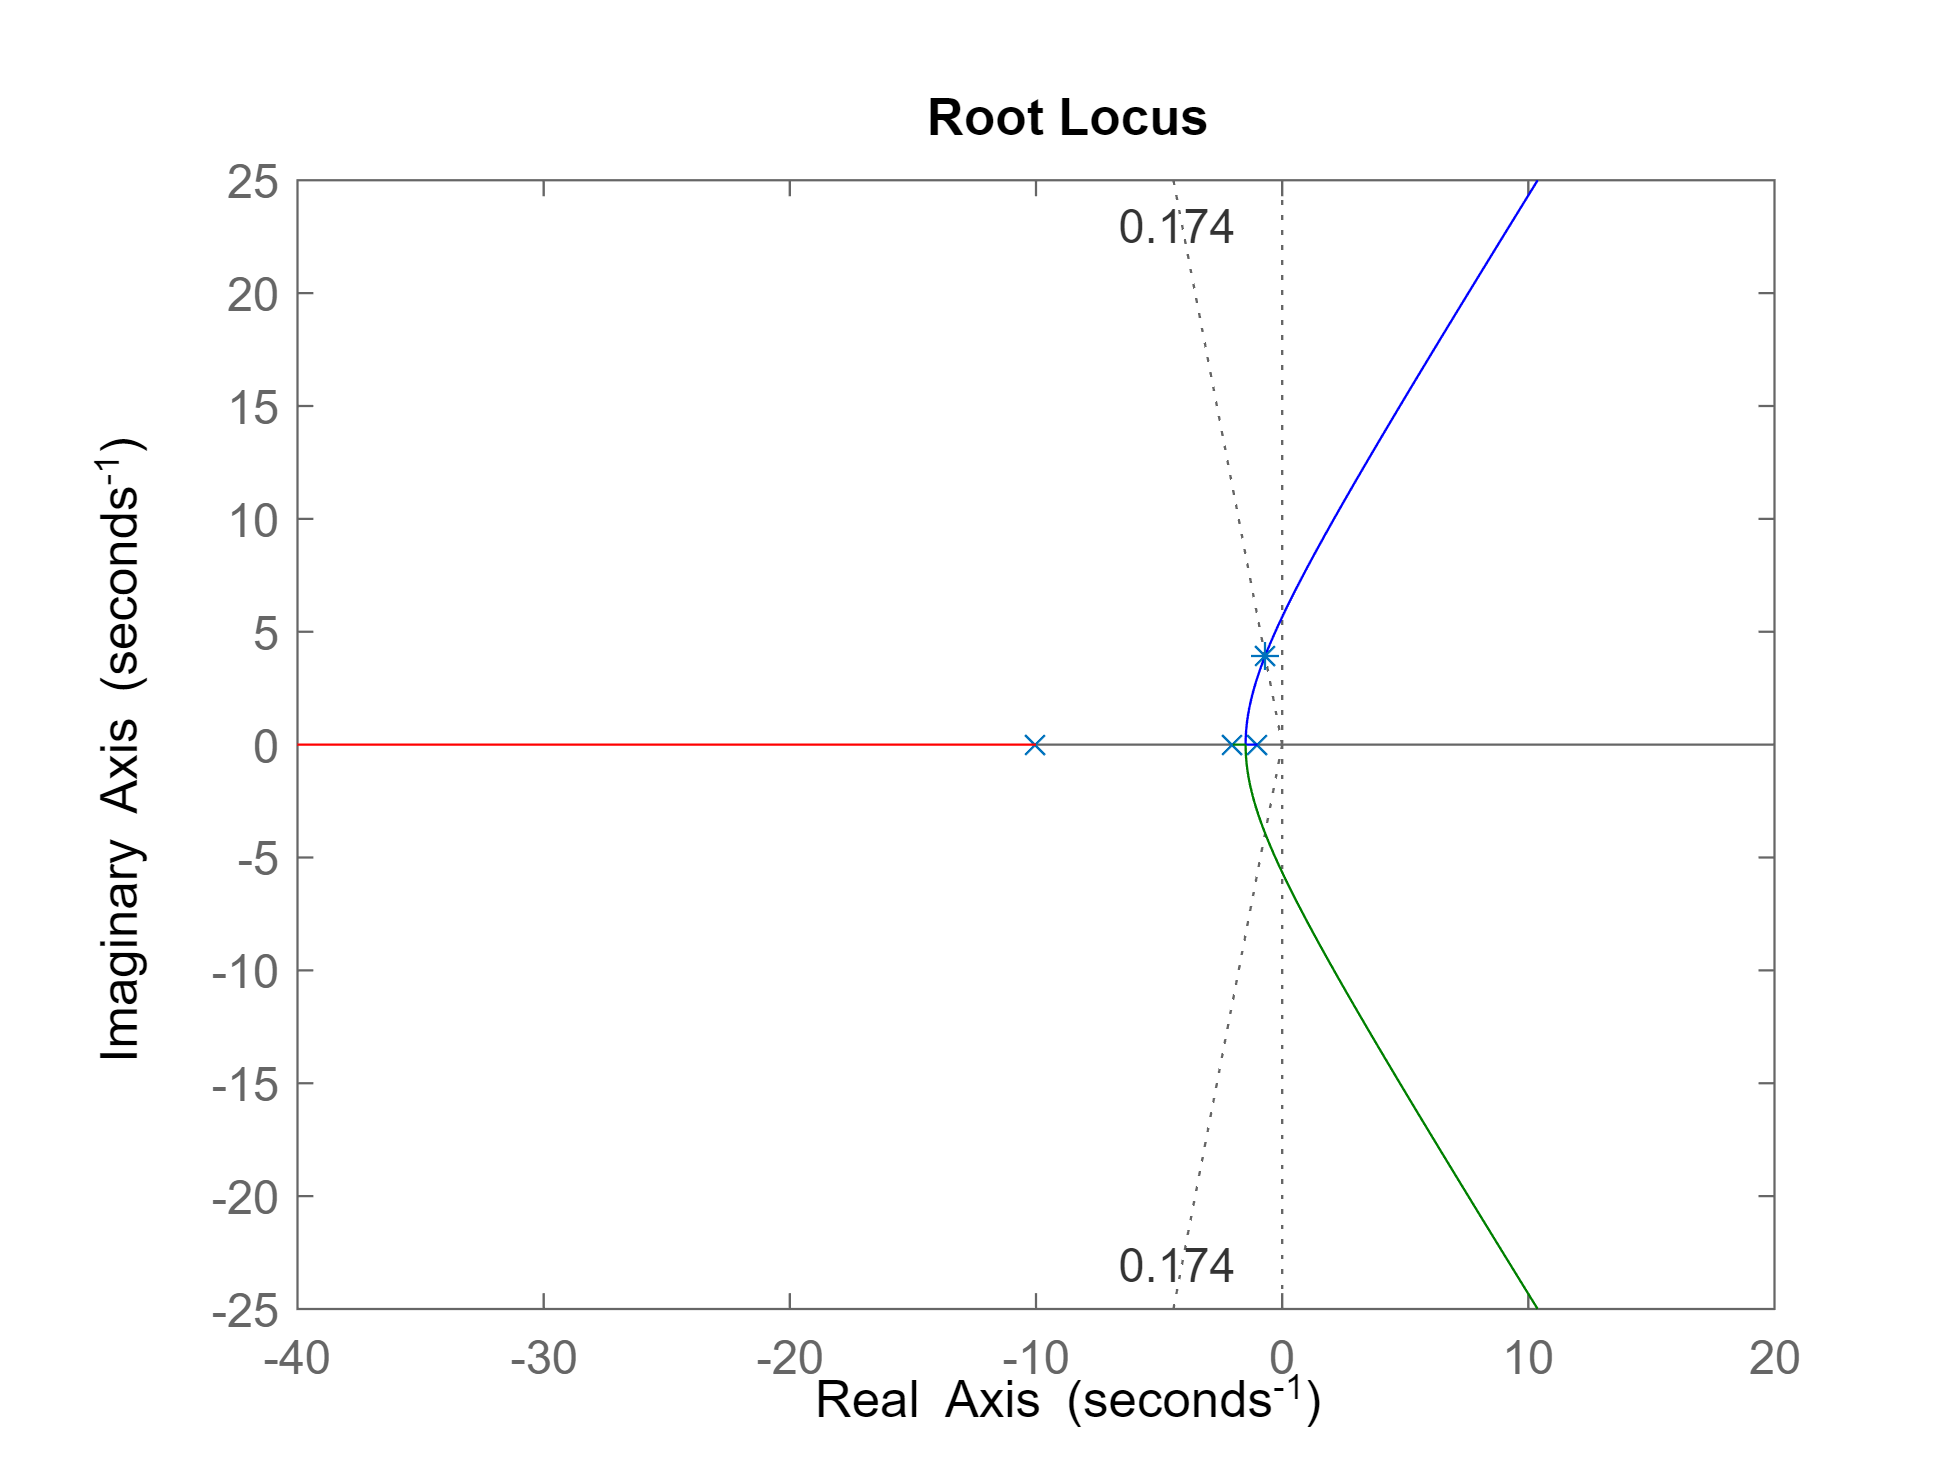

Current plot released


plot(s_1,'*')
hold

K=1/abs(evalfr(G,s_1))

K = 164.5653

For a type zero system that is stable in the closed loop $e_{ss}=\frac{1}{1+K_p}$ where $K_p=\lim_{s\rightarrow 0}KG(s)$

K_p=evalfr(K*G,0)

K_p = 8.2283

e_ss=1/(1+K_p)

e_ss = 0.1084

Gcl=feedback(K*G,1)

Gcl =
 
               164.57
  --------------------------------
  (s+11.61) (s^2 + 1.387s + 15.89)
 
Continuous-time zero/pole/gain model.



rlocus(G)
hold

Current plot held


p=pole(Gcl)

p =  -11.6130 + 0.0000i
  -0.6935 + 3.9258i
  -0.6935 - 3.9258i


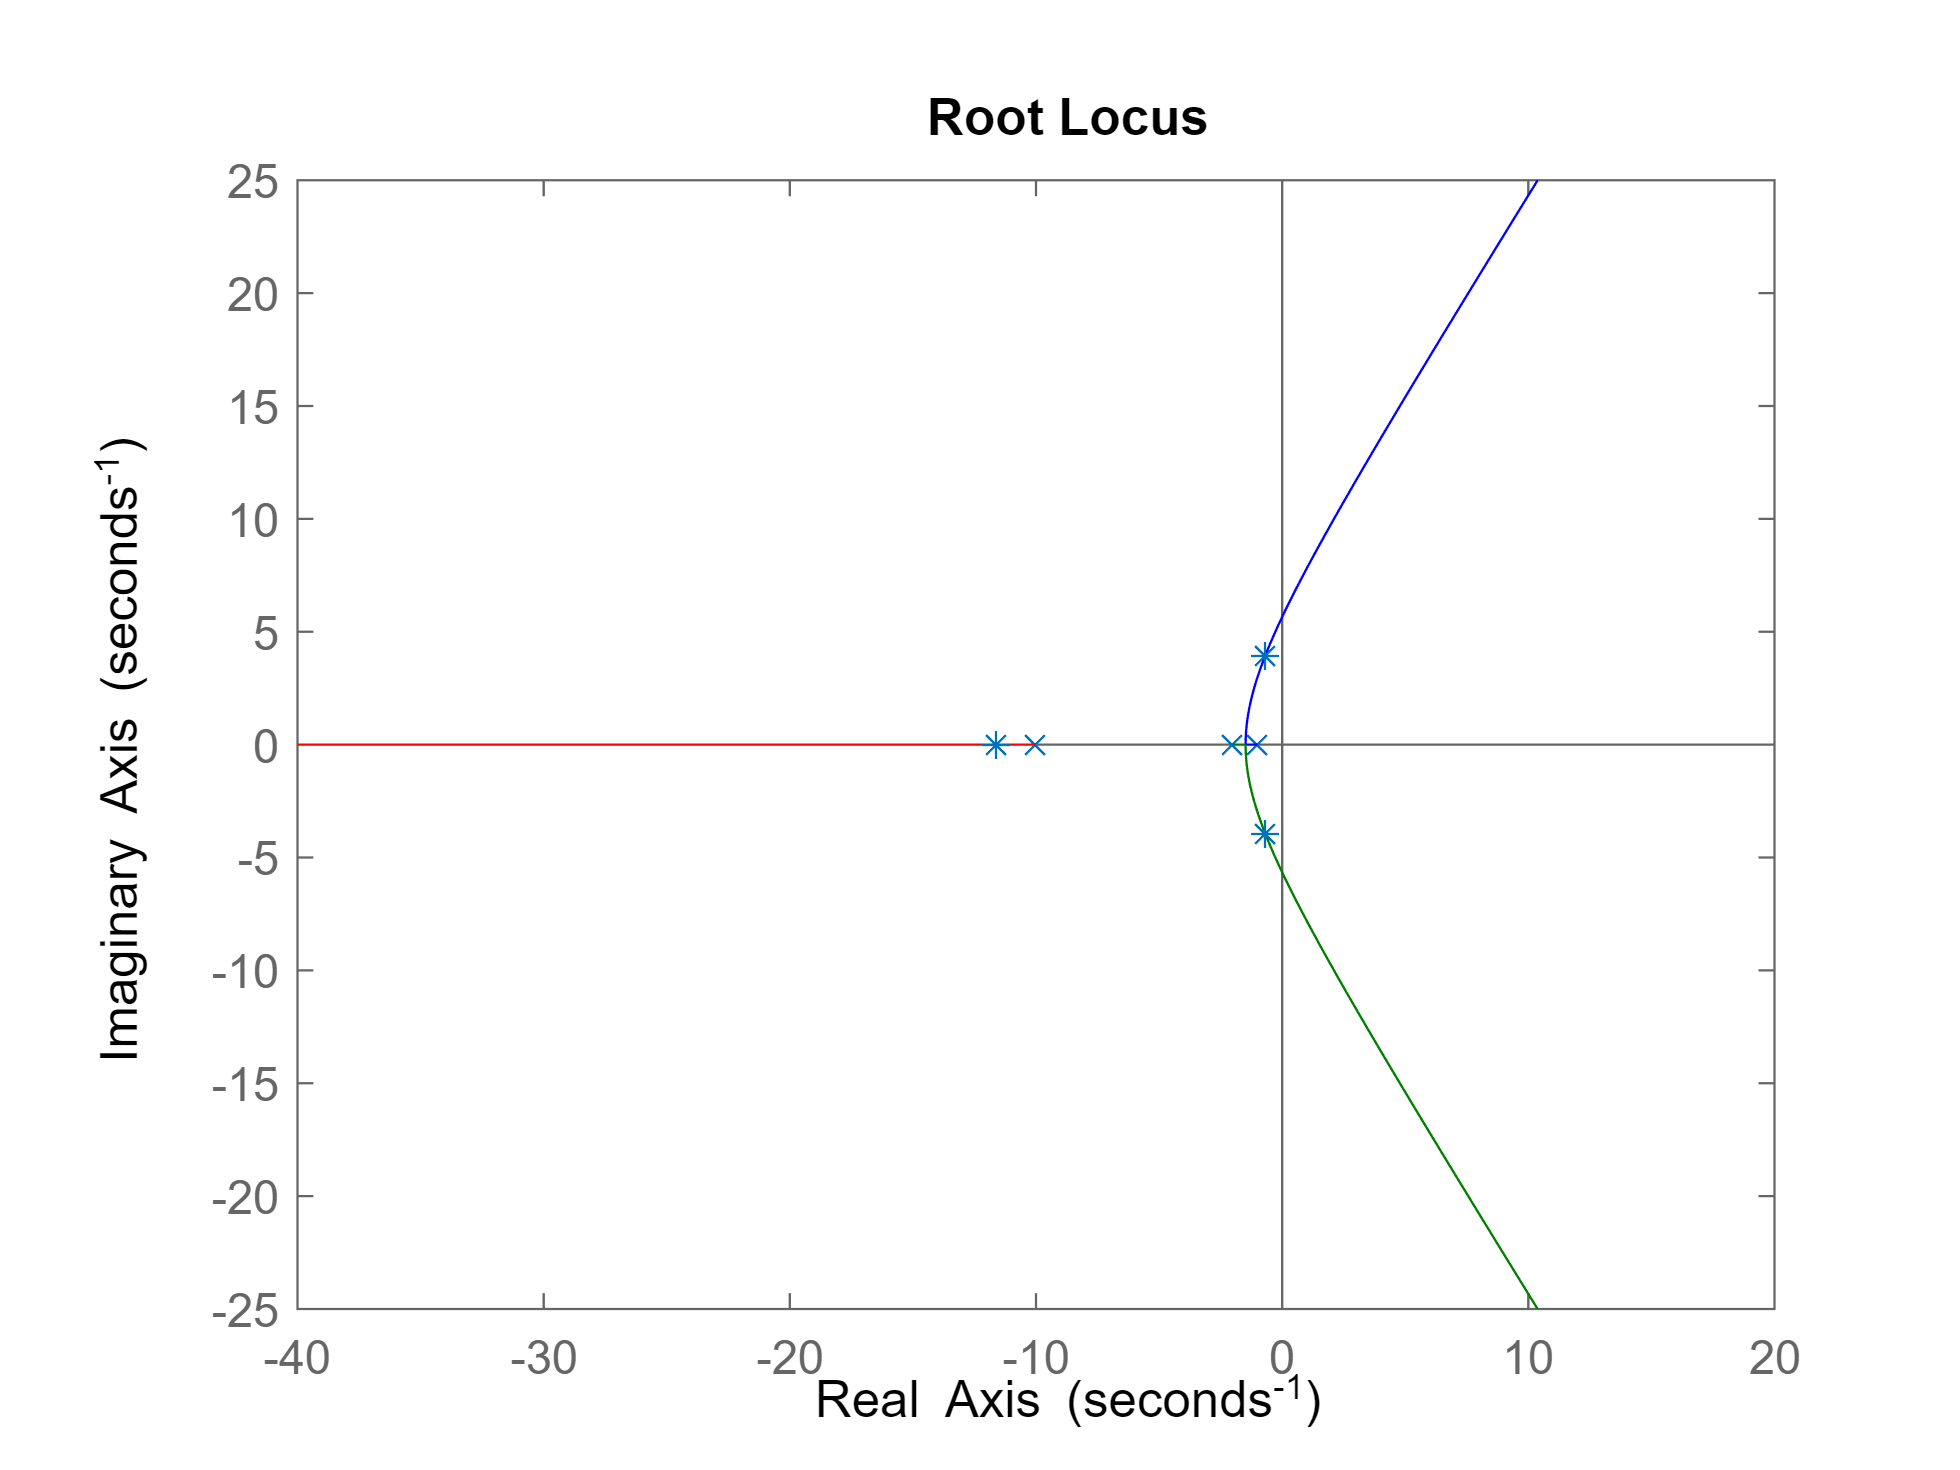

Current plot released


plot(p,'*')
hold

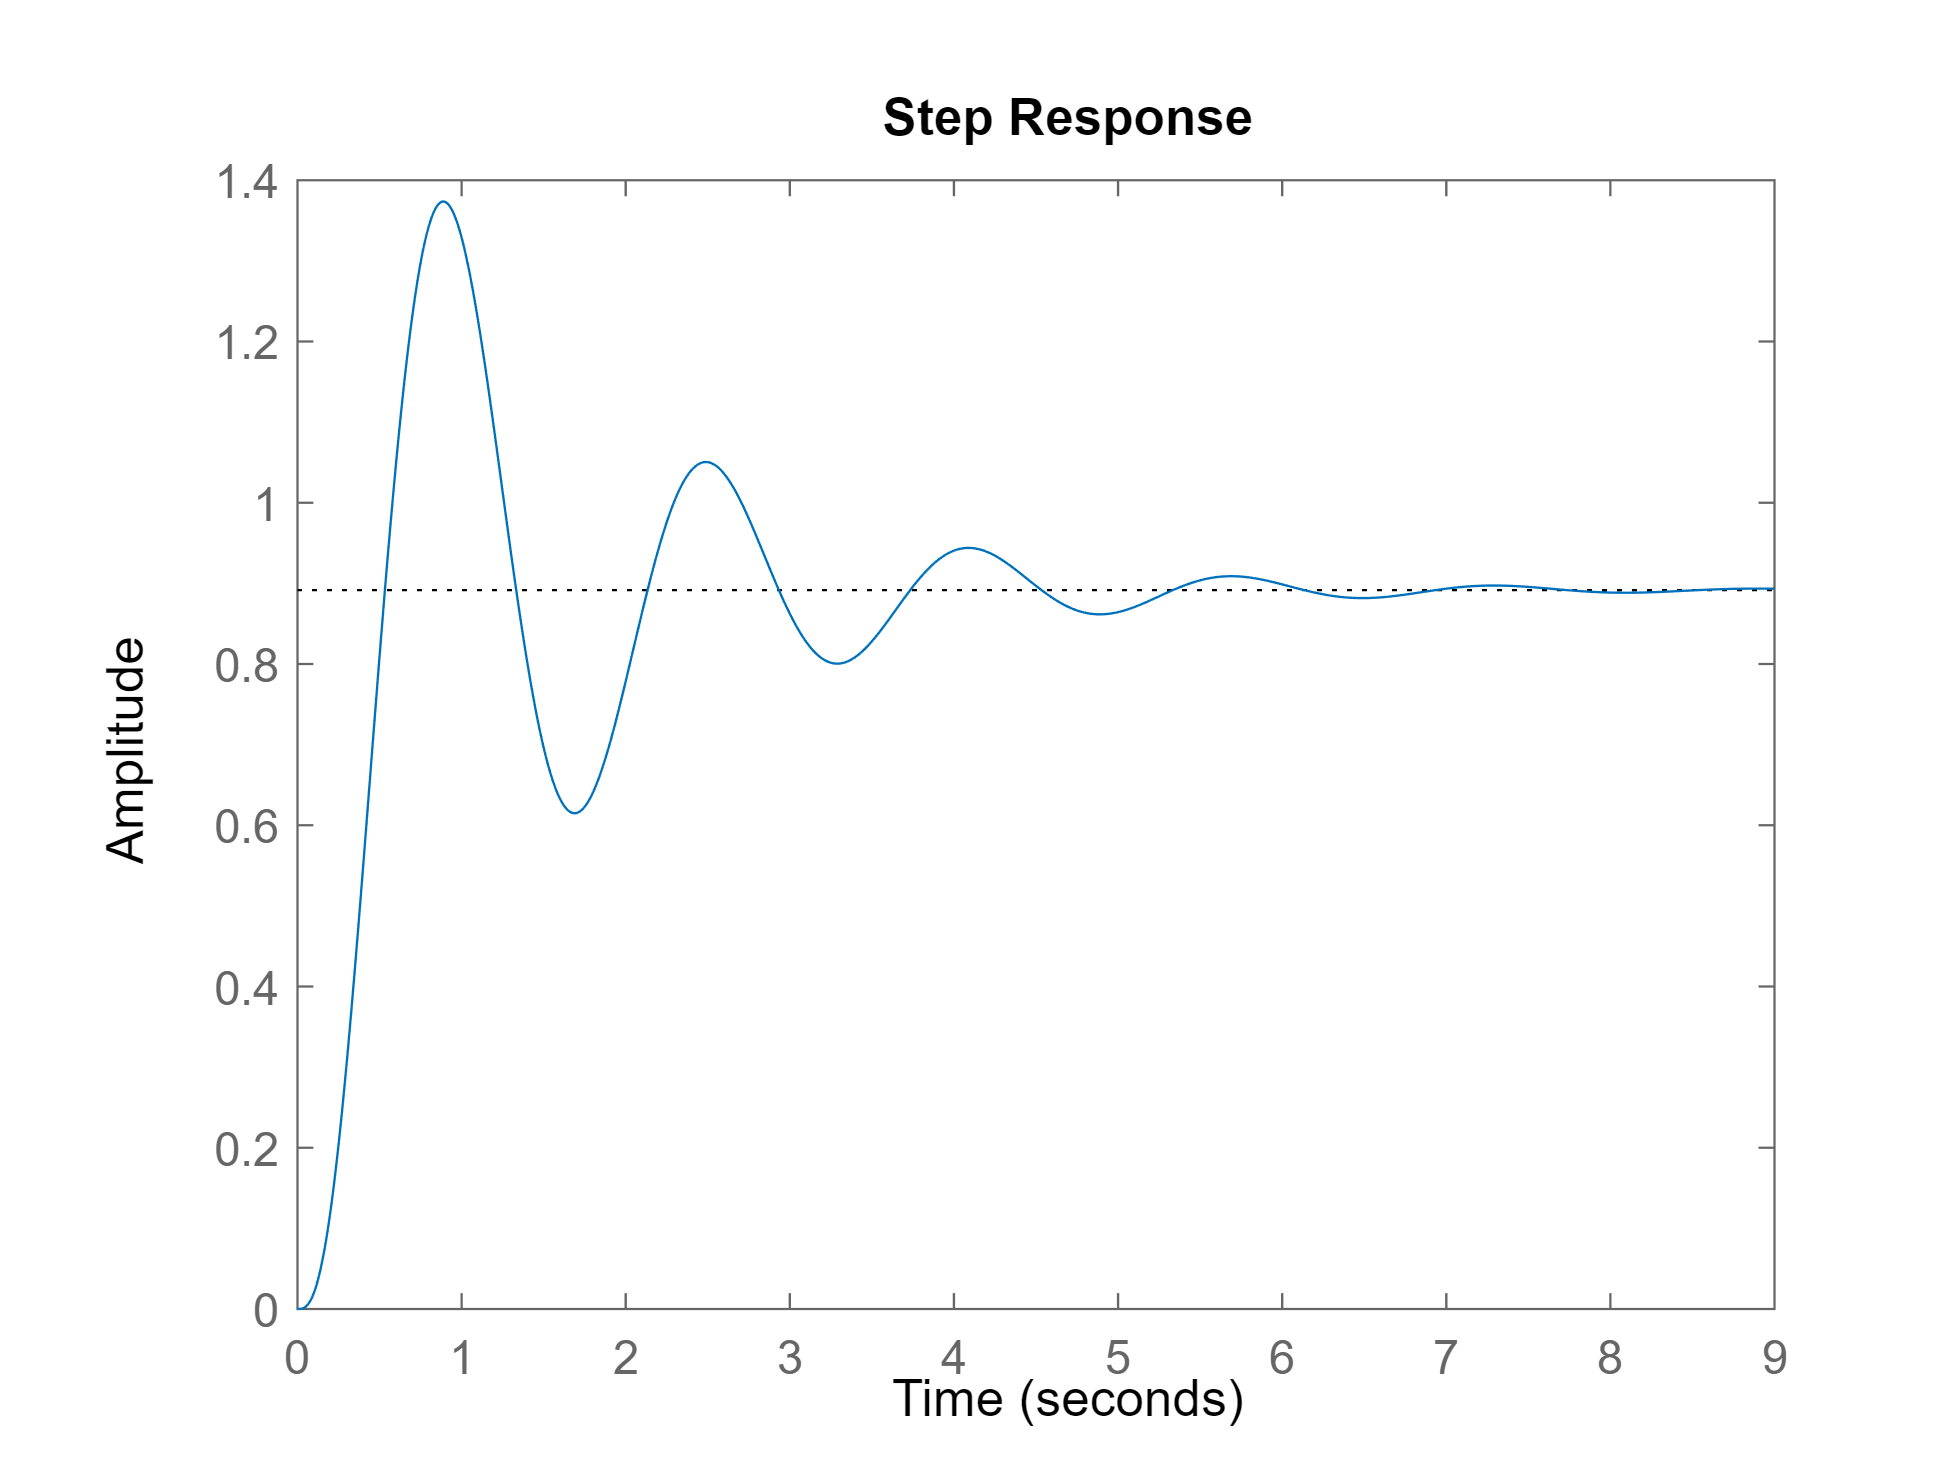

step(Gcl)

From the above graph we see that for a unit step input the system has a steady state error of approximately 0.1 after about time $t=6$ or $t=7$. 

We know that an integral controller instead of a proportional controller would eliminate the steady state error. So lets try that.

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



rlocus(G/s)
sgrid(zeta,0)
K=23.5

K = 23.5000

GclI=feedback(K*G/s,1)

GclI =
 
                     23.5
  -------------------------------------------
  (s+9.967) (s+2.701) (s^2 + 0.3321s + 0.873)
 
Continuous-time zero/pole/gain model.



hold

Current plot held


p=pole(GclI)

p =   -9.9670 + 0.0000i
  -0.1661 + 0.9195i
  -0.1661 - 0.9195i
  -2.7009 + 0.0000i


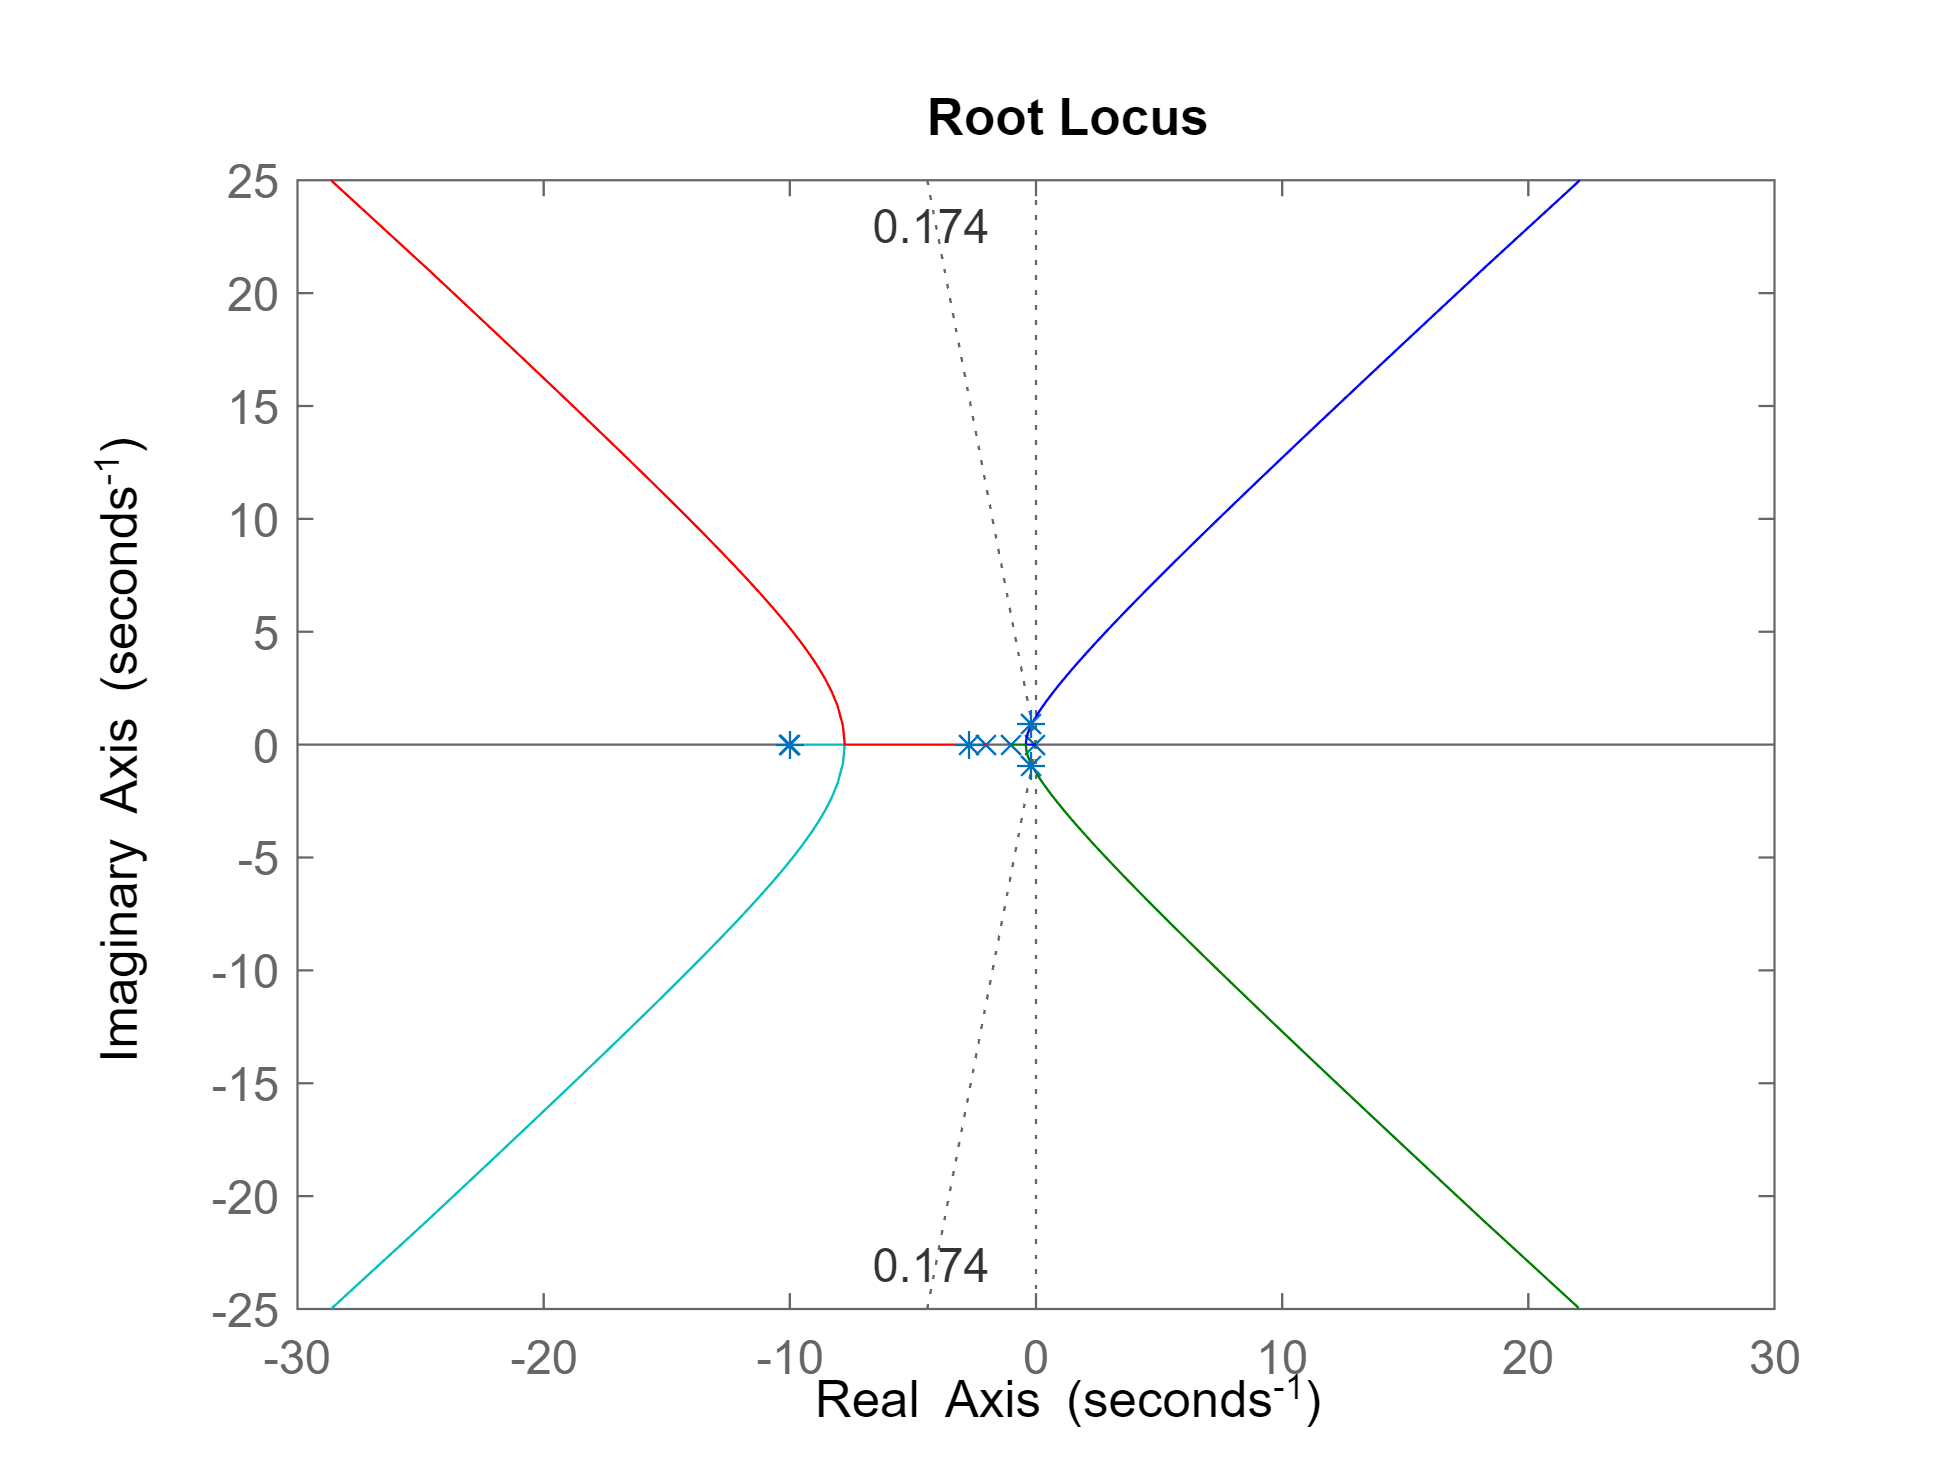

Current plot released


plot(p,"*")
hold

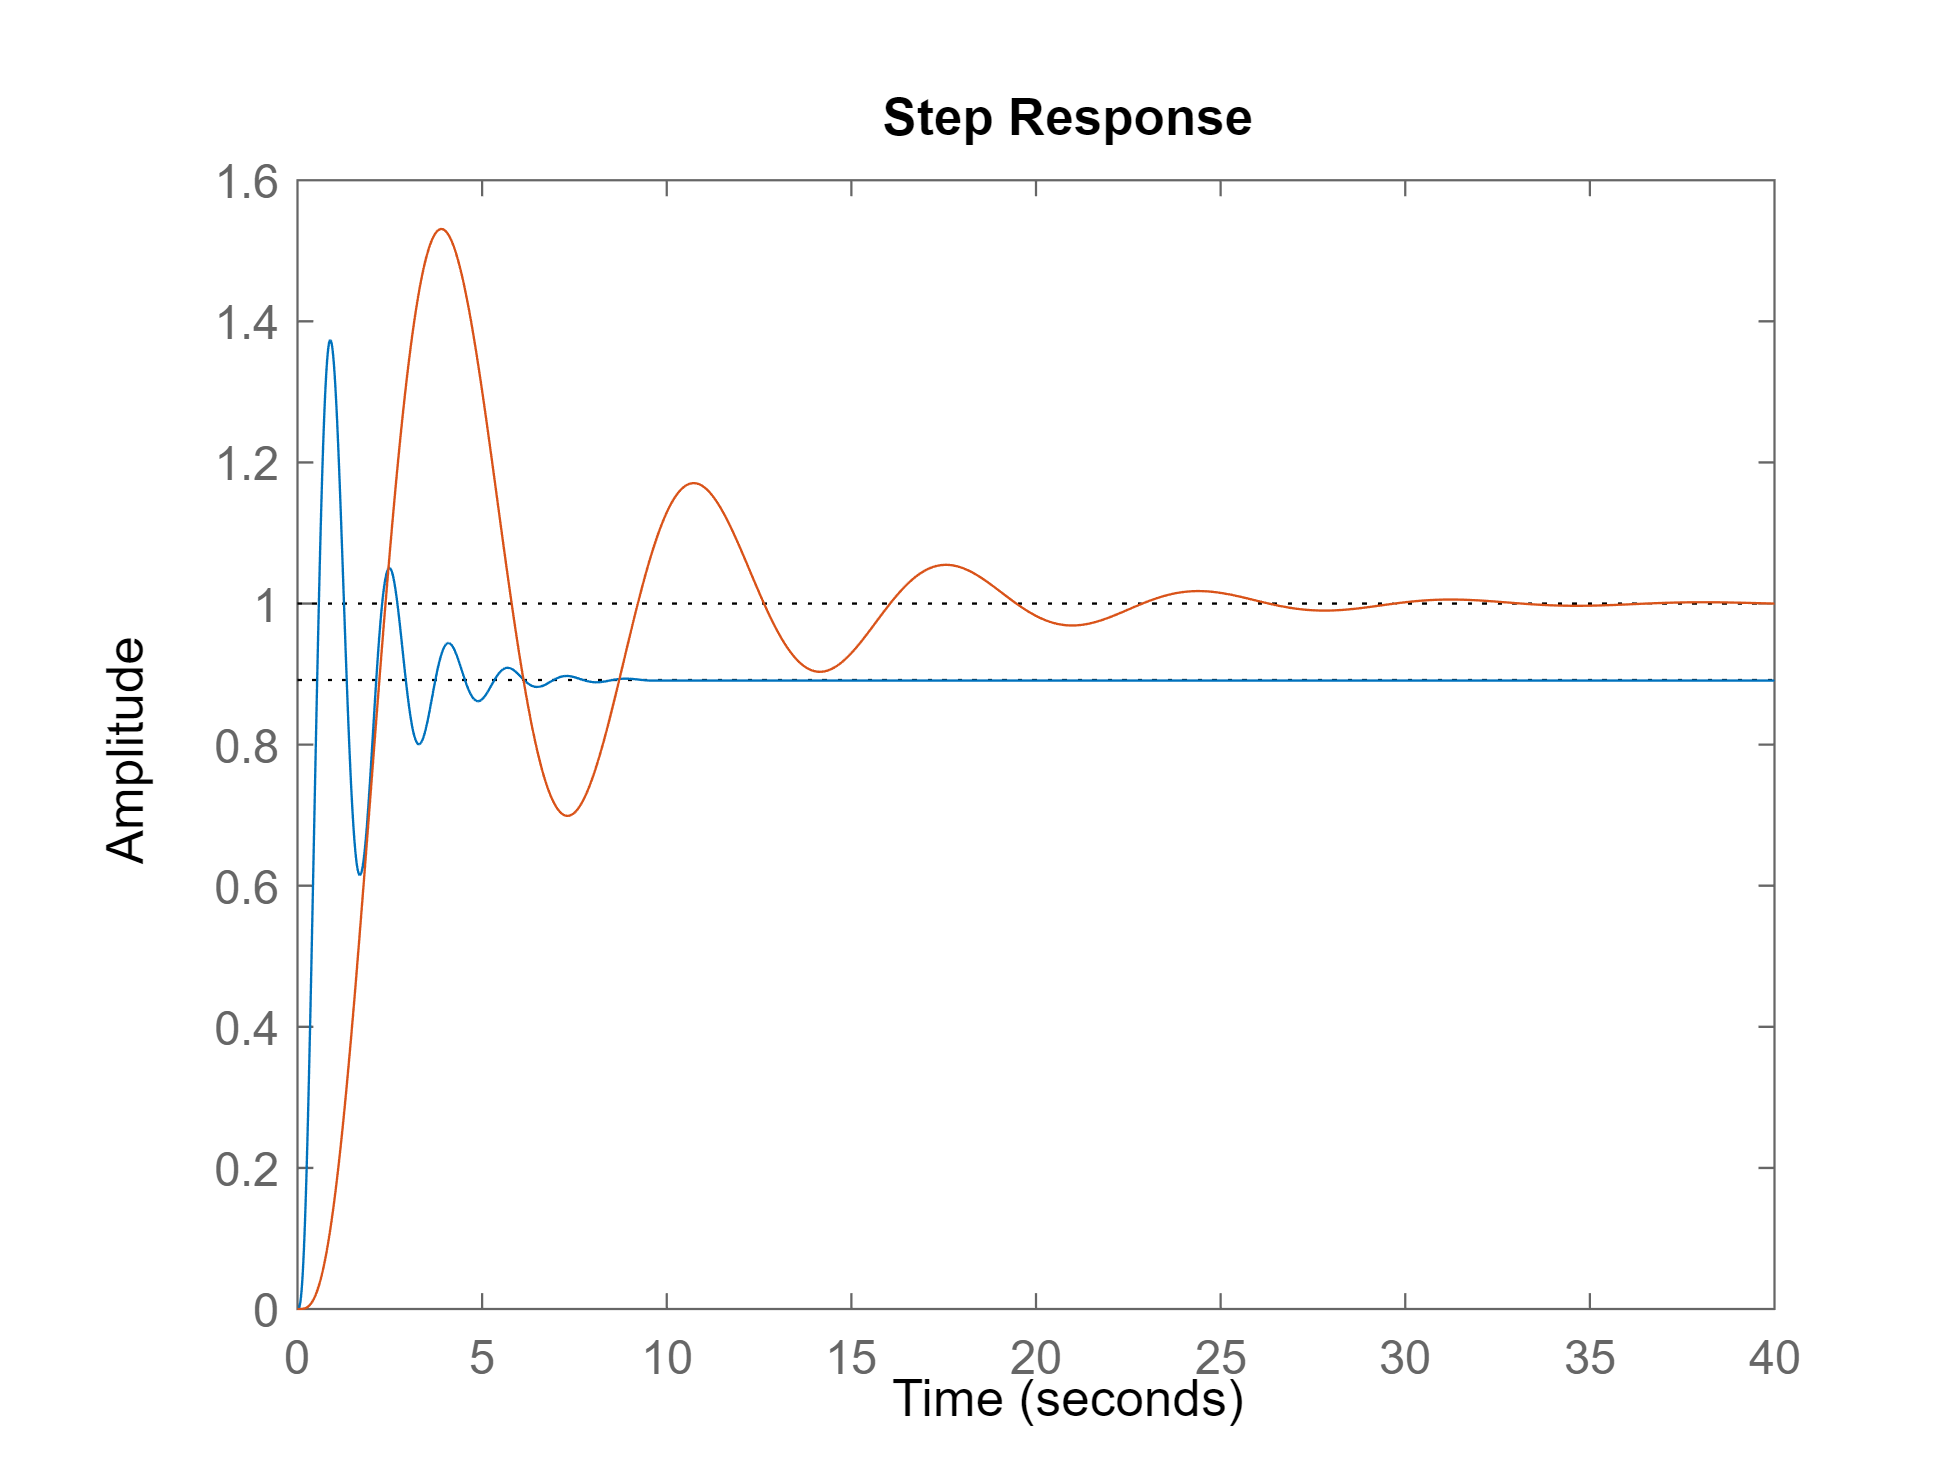

step(Gcl,GclI)

We see that we have zero steady state error but that we have increased the % overshoot and almost tripled the settling time to around 20 seconds.

We can actually do better if we do a PI controller by adding a zero close to the integral pole at $s=0$ so that there will be pole/zero cancellation. 

rlocus((s+.1)/s*G)
sgrid(zeta,0)
s2=-0.678+j*3.837

s2 = -0.6780 + 3.8370i

K=1/abs(evalfr((s+.1)/s*G,s2))

K = 158.1846

Gcl3=feedback(K*(s+.1)/s*G,1)

Gcl3 =
 
                 158.18 (s+0.1)
  --------------------------------------------
  (s+11.55) (s+0.09018) (s^2 + 1.355s + 15.18)
 
Continuous-time zero/pole/gain model.



p=pole(Gcl3)

p =  -11.5549 + 0.0000i
  -0.6774 + 3.8368i
  -0.6774 - 3.8368i
  -0.0902 + 0.0000i


hold

Current plot held


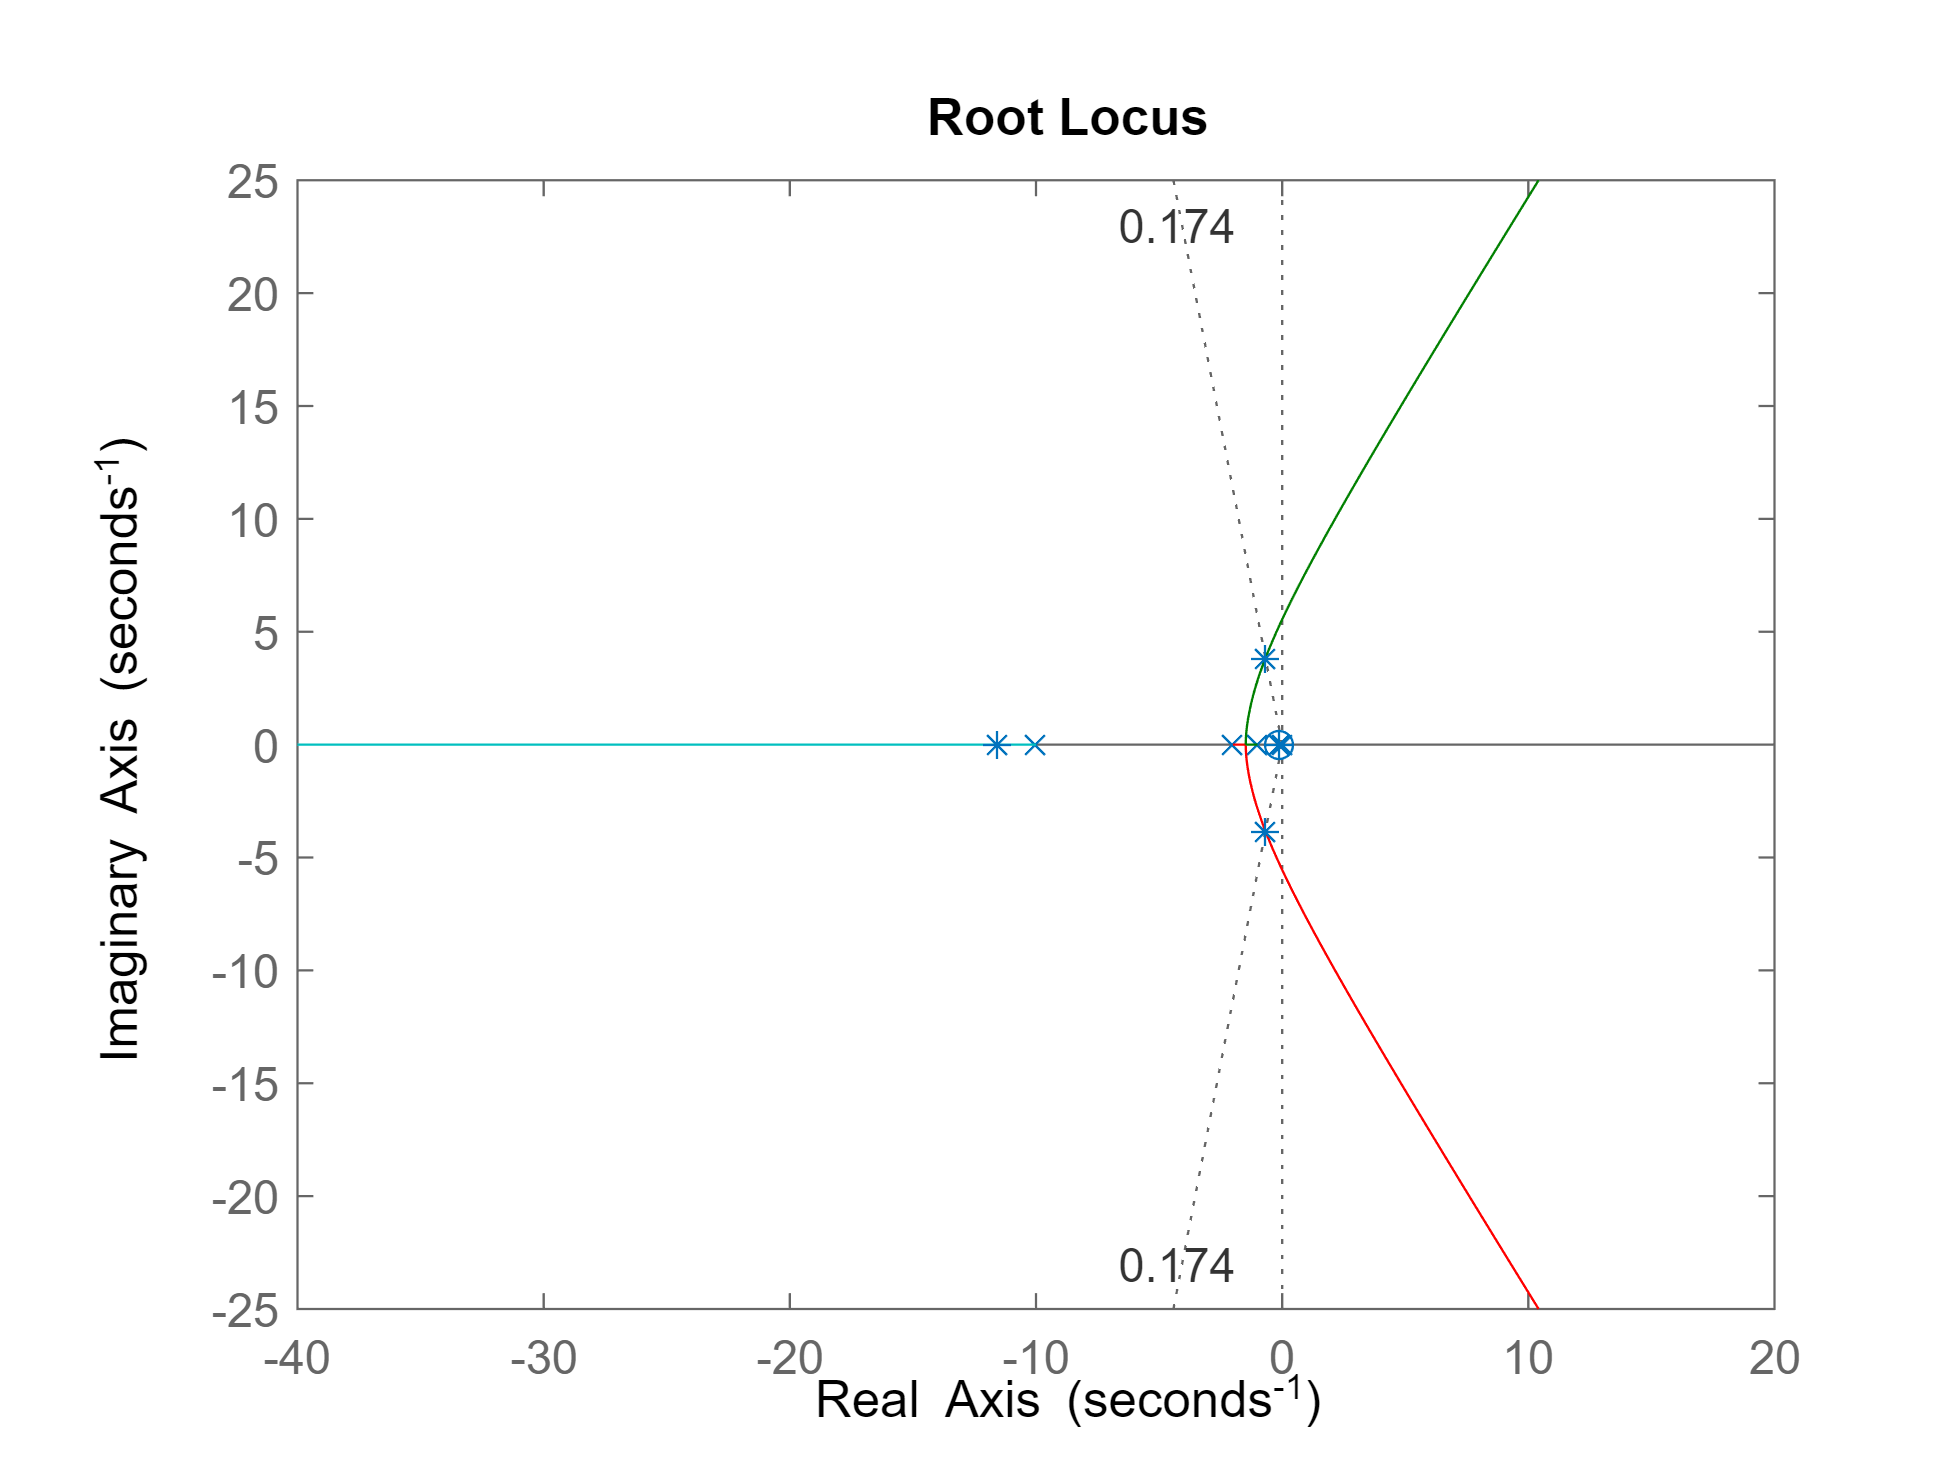

Current plot released


plot(p,'*')
hold

step(Gcl3)
hold

Current plot held


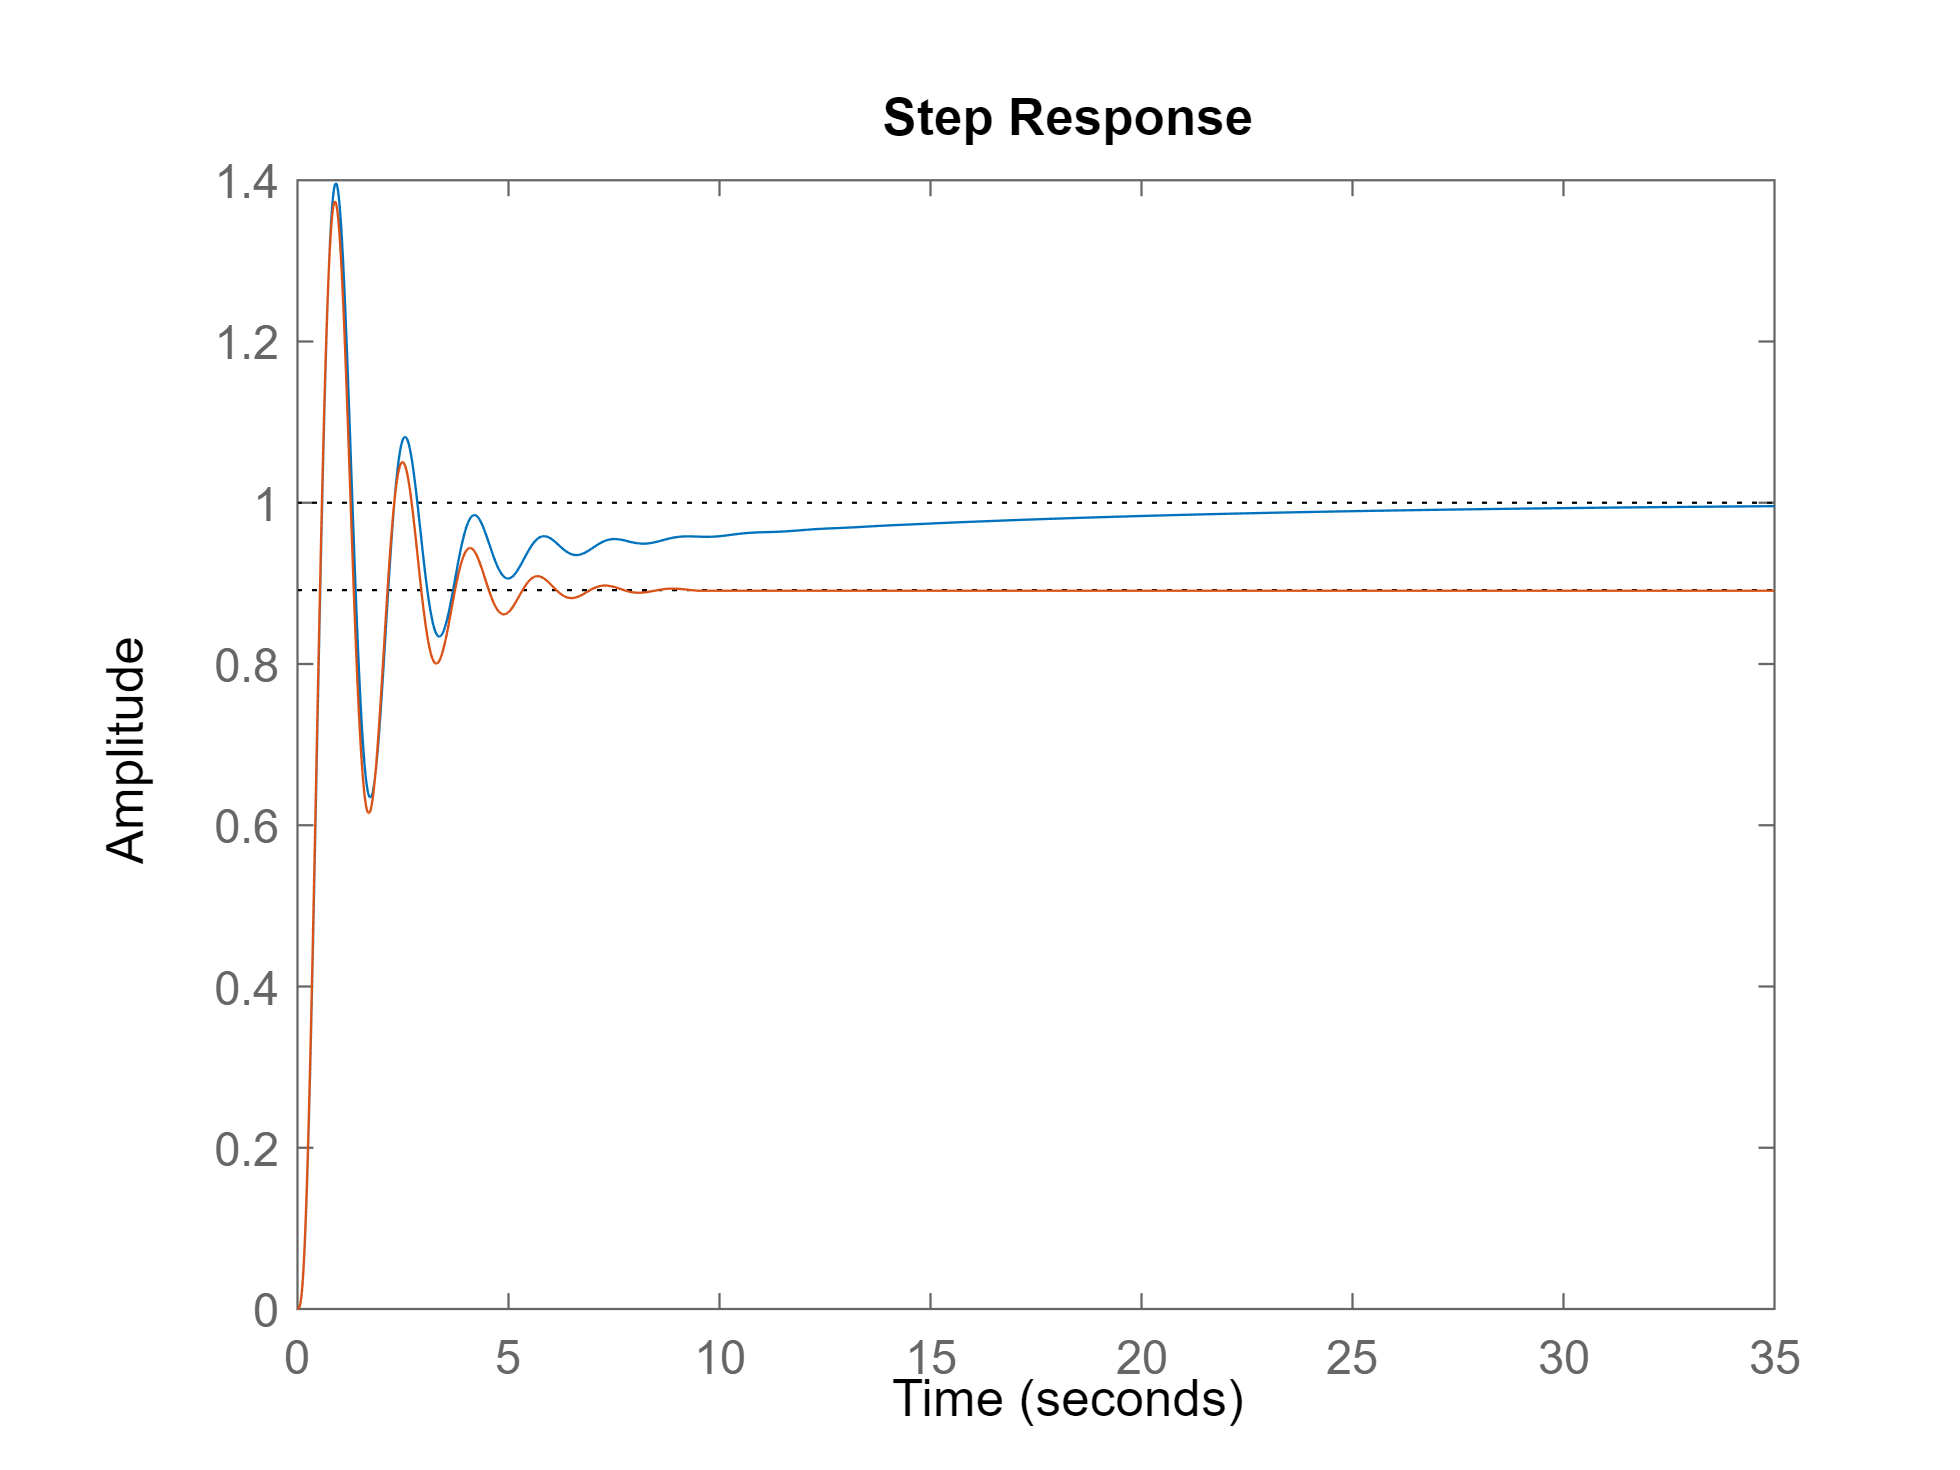

Current plot released


step(Gcl)
hold

### Compensator Design

#### Lag Compensation

The intuition behind a lag controller is to replace the pole at the origin in a PI controller with a pole that is close to the origin and approximates a pole at the origin. It does not completely eliminate the steady state error but it does reduce it.

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



Zc=0.5

Zc = 0.5000

Pc=0.1

Pc = 0.1000

C=(s+Zc)/(s+Pc)

C =
 
  s + 0.5
  -------
  s + 0.1
 
Continuous-time transfer function.



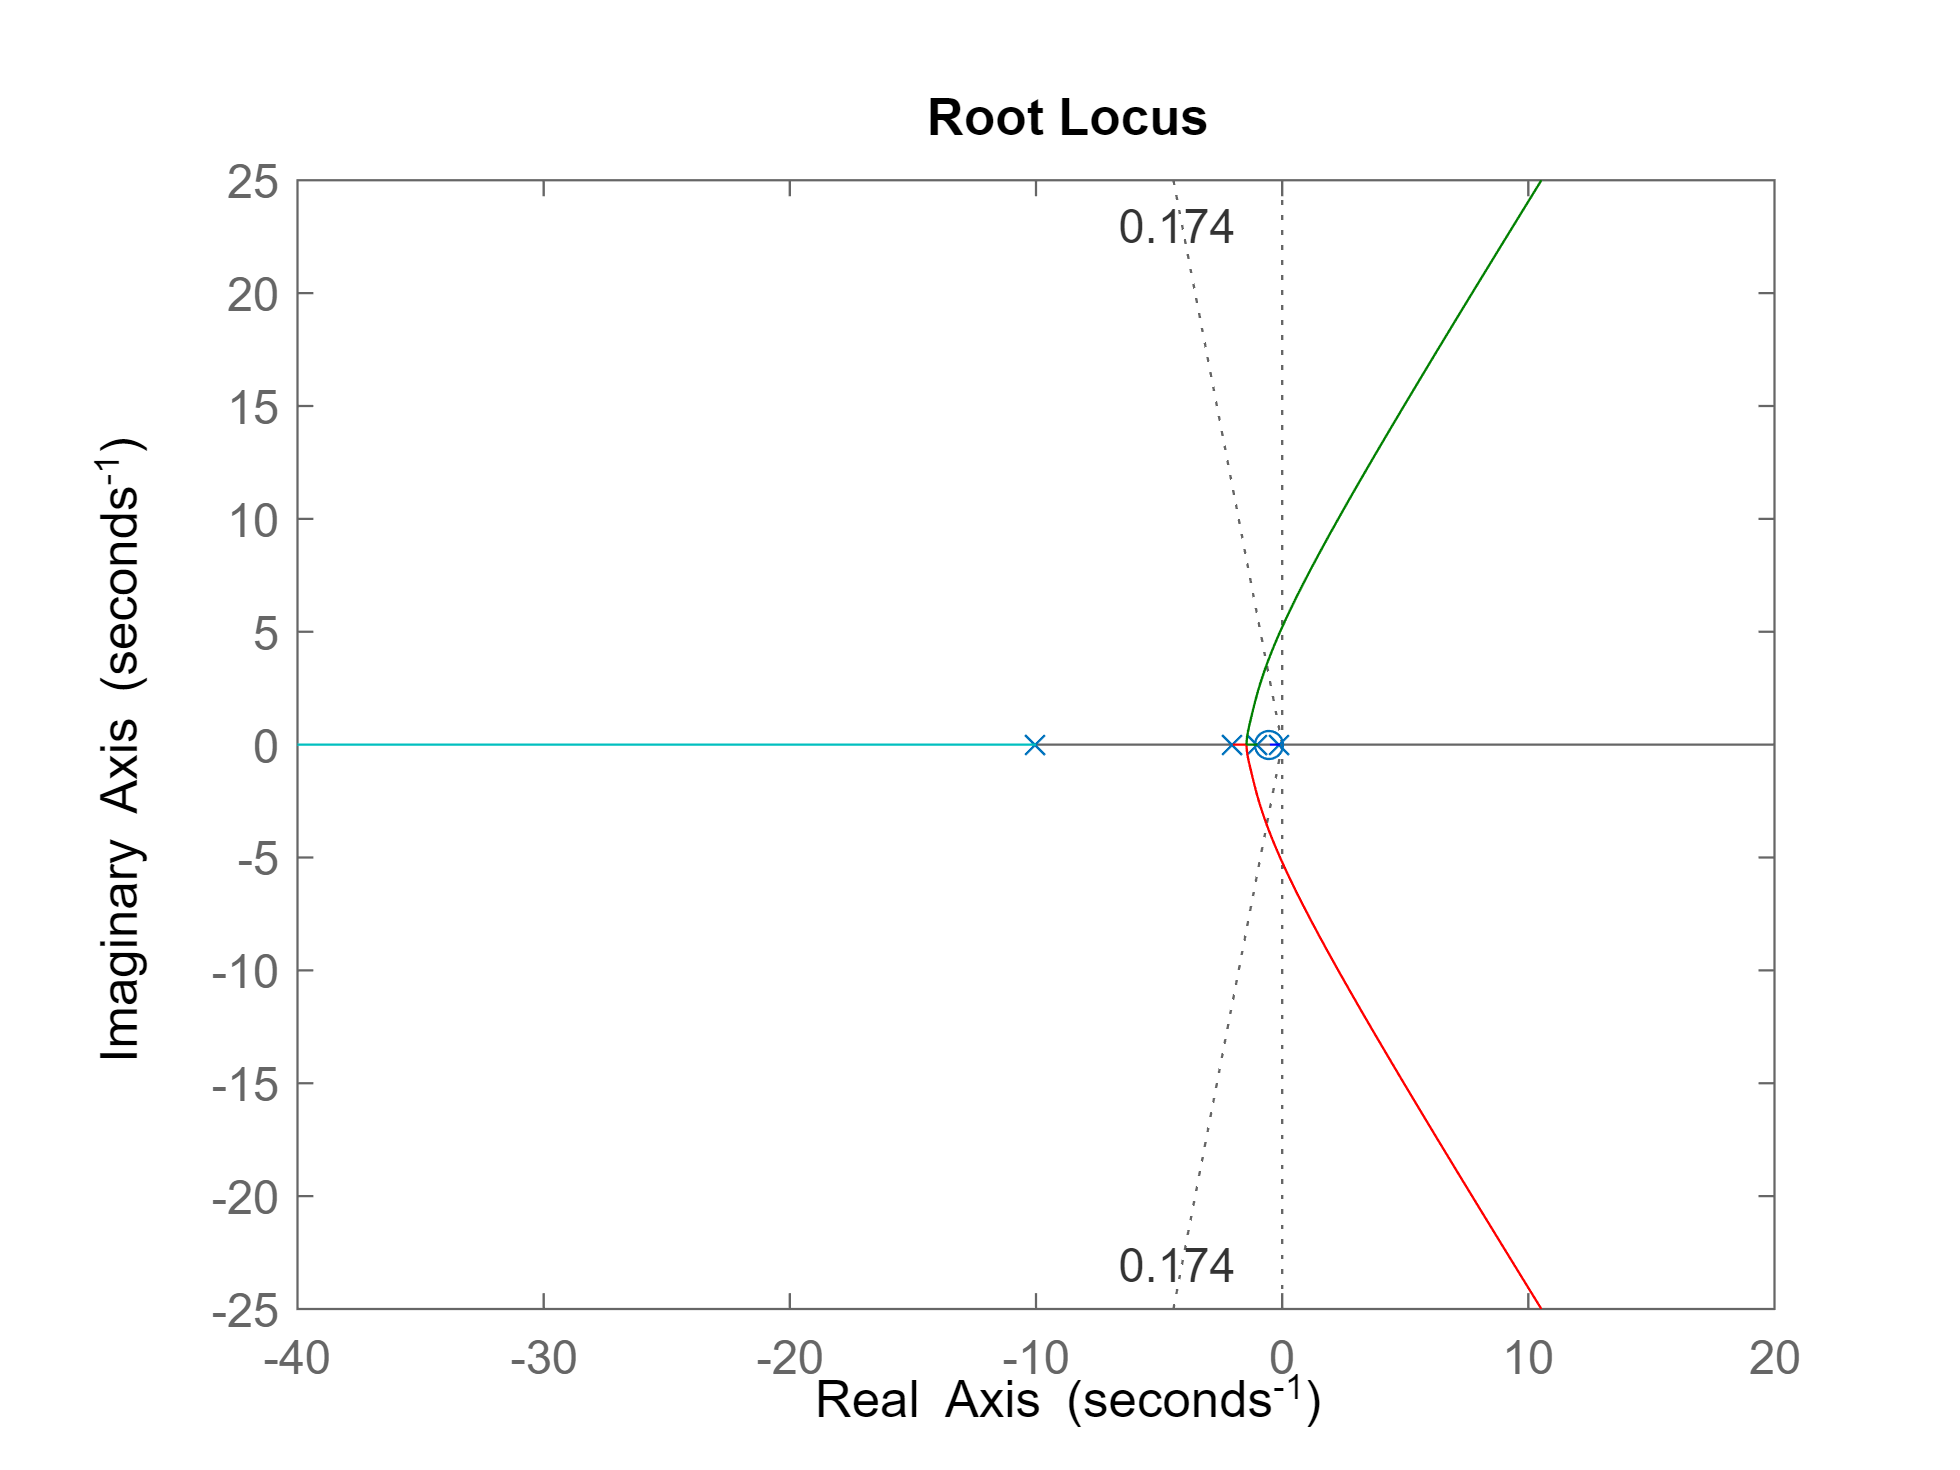

rlocus(C*G)
sgrid(zeta,0)

Let's search along the line of constant damping ratio $\zeta$ to get an approximate value of $s$ that lies on the root locus that we can use to get a $K$ value. For second order complex conjugate poles (ie. $0<\zeta<1$ we have $\theta=\cos^{-1}\zeta$ in the diagram below showing the pole locations.

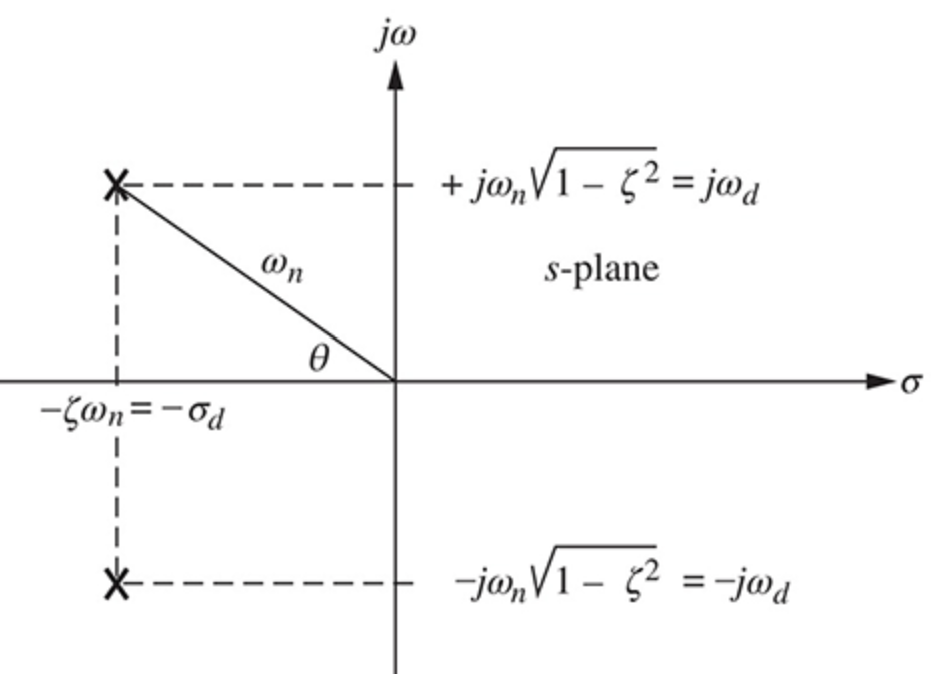

So in our case

theta=acos(zeta)

theta = 1.3959

We can get a line of points corresponding to that constant damping ratio with the command:

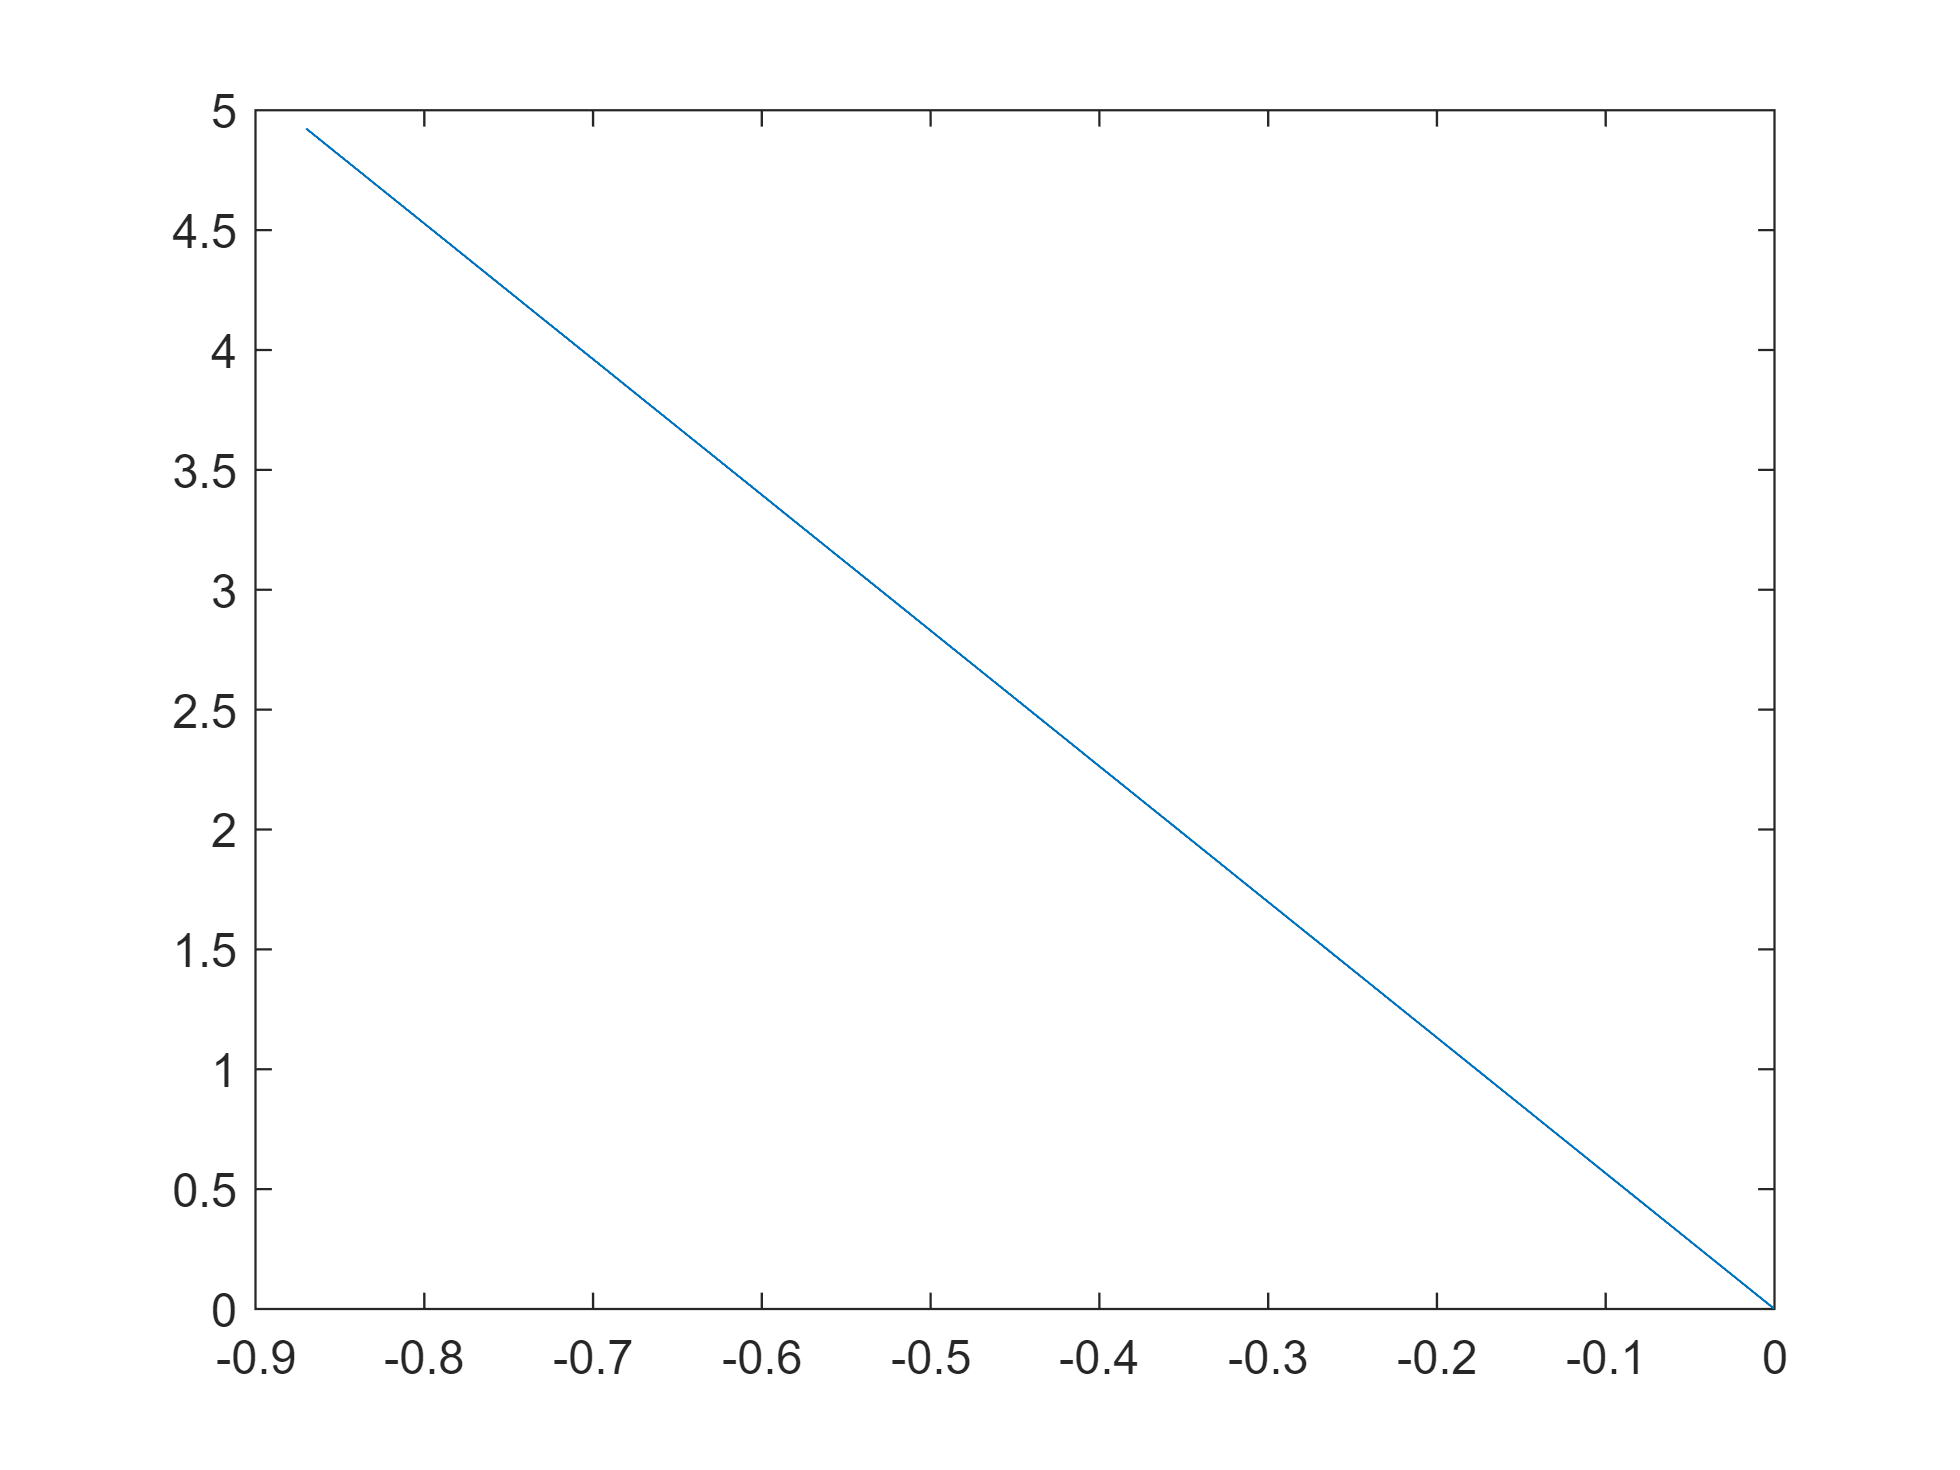

r=0:.001:5;
zetaPoints=exp(j*(pi-theta))*r;
plot(zetaPoints)

Lets evaluate the angle of $C(s)G(s)$ at those points to look for odd multiples of $180^\circ$.

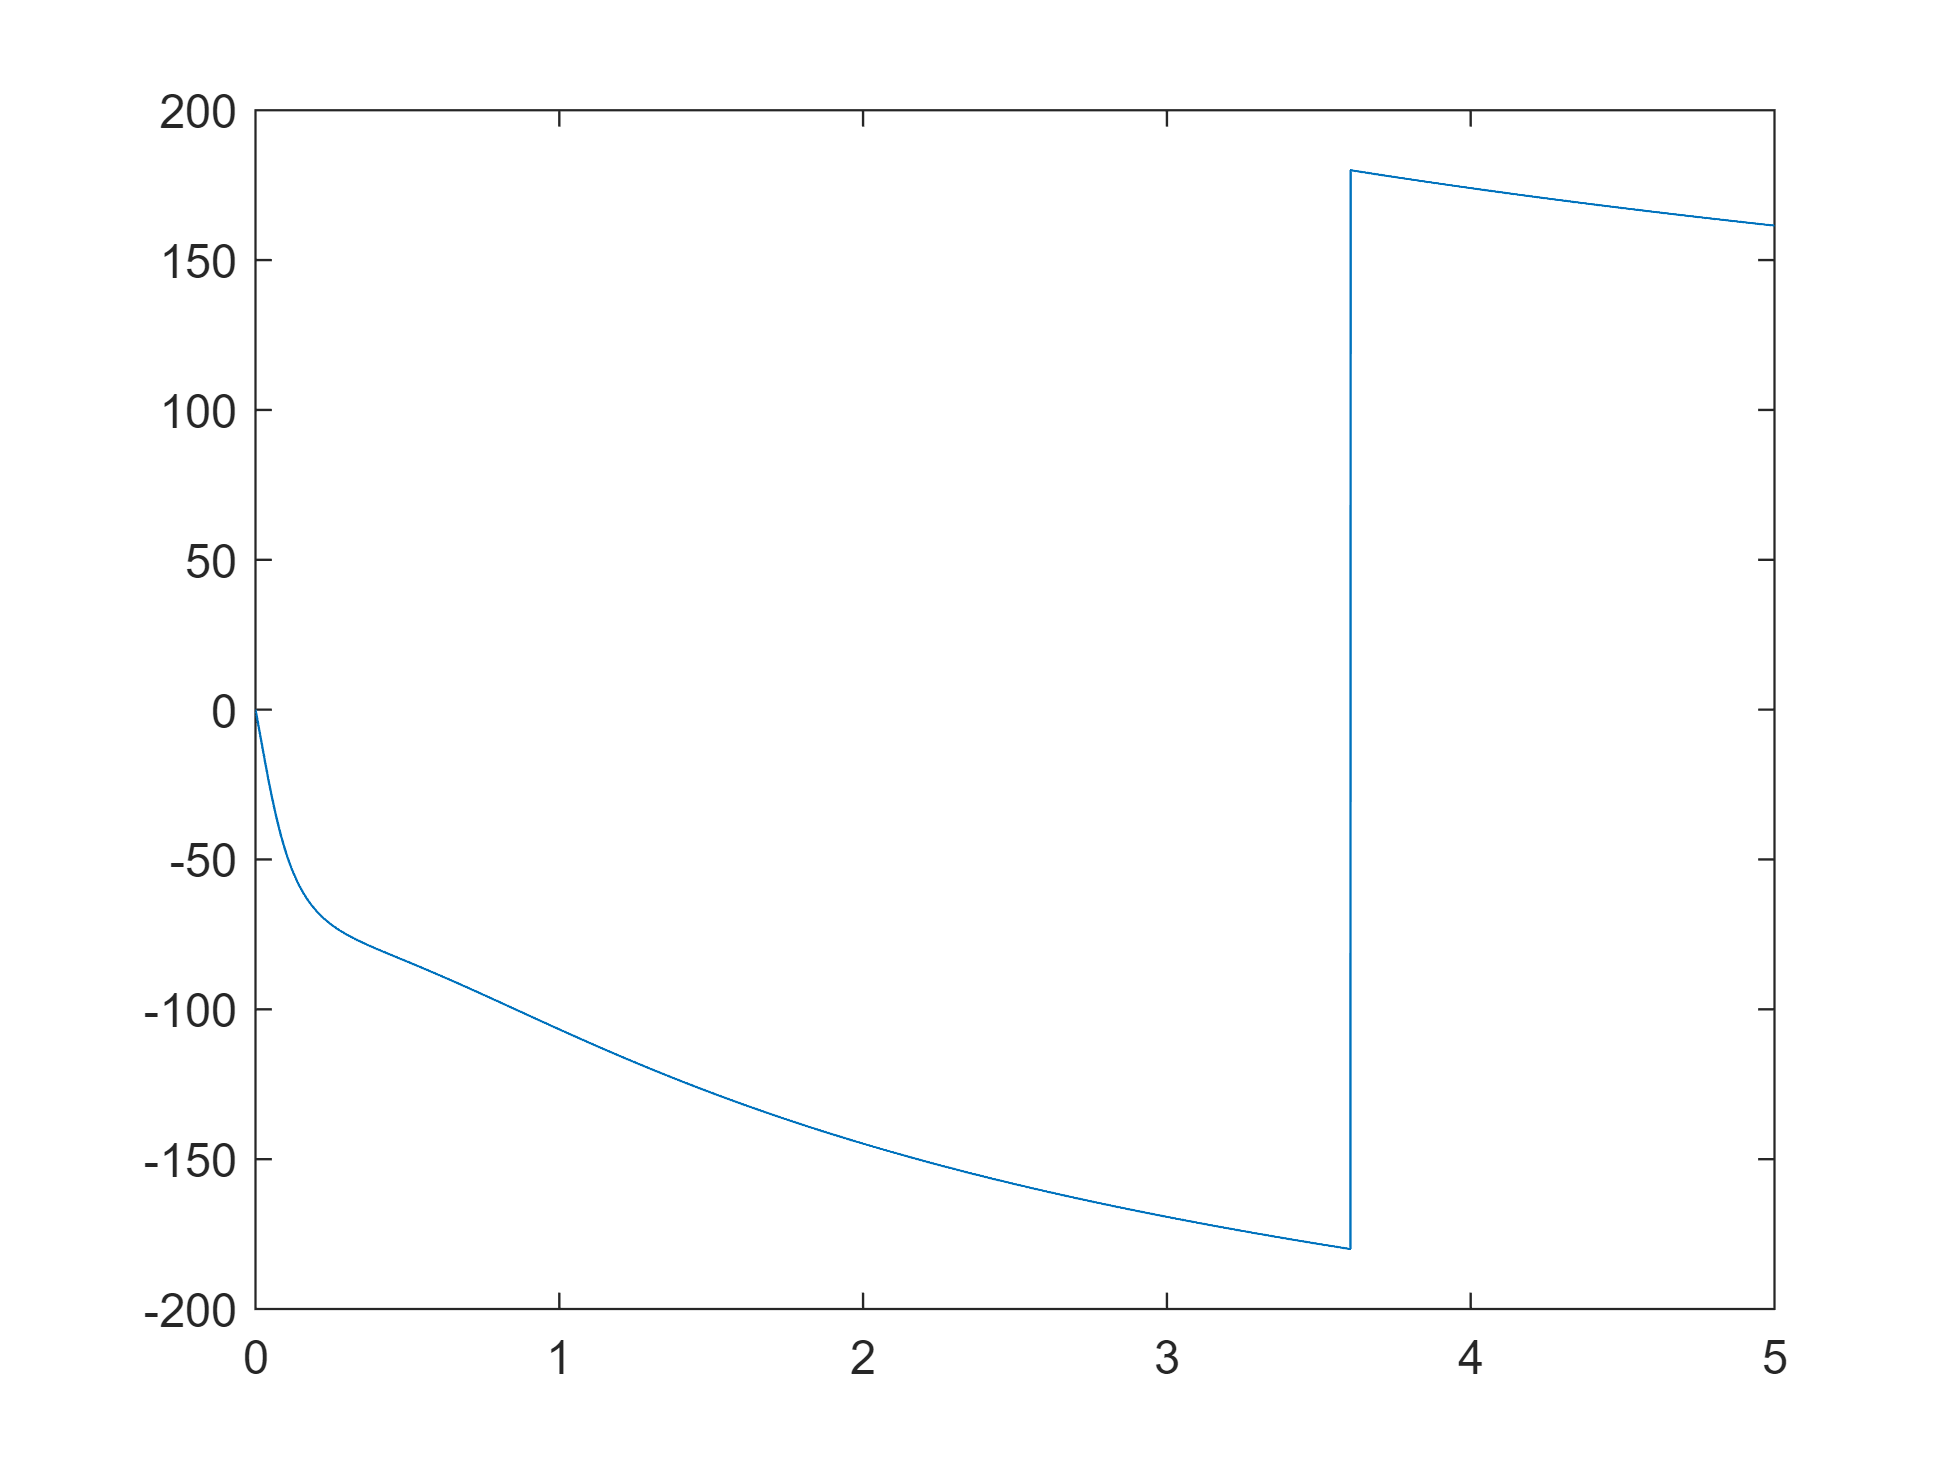

CGangles=angle(freqresp(C*G,zetaPoints))*180/pi;
CGangles=squeeze(CGangles);
plot(r,CGangles)

Do mod $180^\circ$ and find minimum value

[m,i]=min(mod(CGangles,180))

m = 0

i = 1

Better: add $180^\circ$ and find minimum value mod $360^\circ$ since we want odd multiples of $180^\circ$. 

[m,i]=min(mod(CGangles+180,360))

m = 0.0109

i = 3605

myS=zetaPoints(i)

myS = -0.6271 + 3.5490i

evalfr(C*G,myS)

ans = -0.0073 - 0.0000i

%K=126
K=1/abs(evalfr(C*G,myS))

K = 137.5028

Gcl4=feedback(K*C*G,1)

Gcl4 =
 
                 137.5 (s+0.5)
  -------------------------------------------
  (s+11.37) (s+0.4792) (s^2 + 1.255s + 12.99)
 
Continuous-time zero/pole/gain model.



p=pole(Gcl4)

p =  -11.3660 + 0.0000i
  -0.6274 + 3.5491i
  -0.6274 - 3.5491i
  -0.4792 + 0.0000i


%hold
rlocus(C*G)
sgrid(zeta,0)
hold

Current plot held


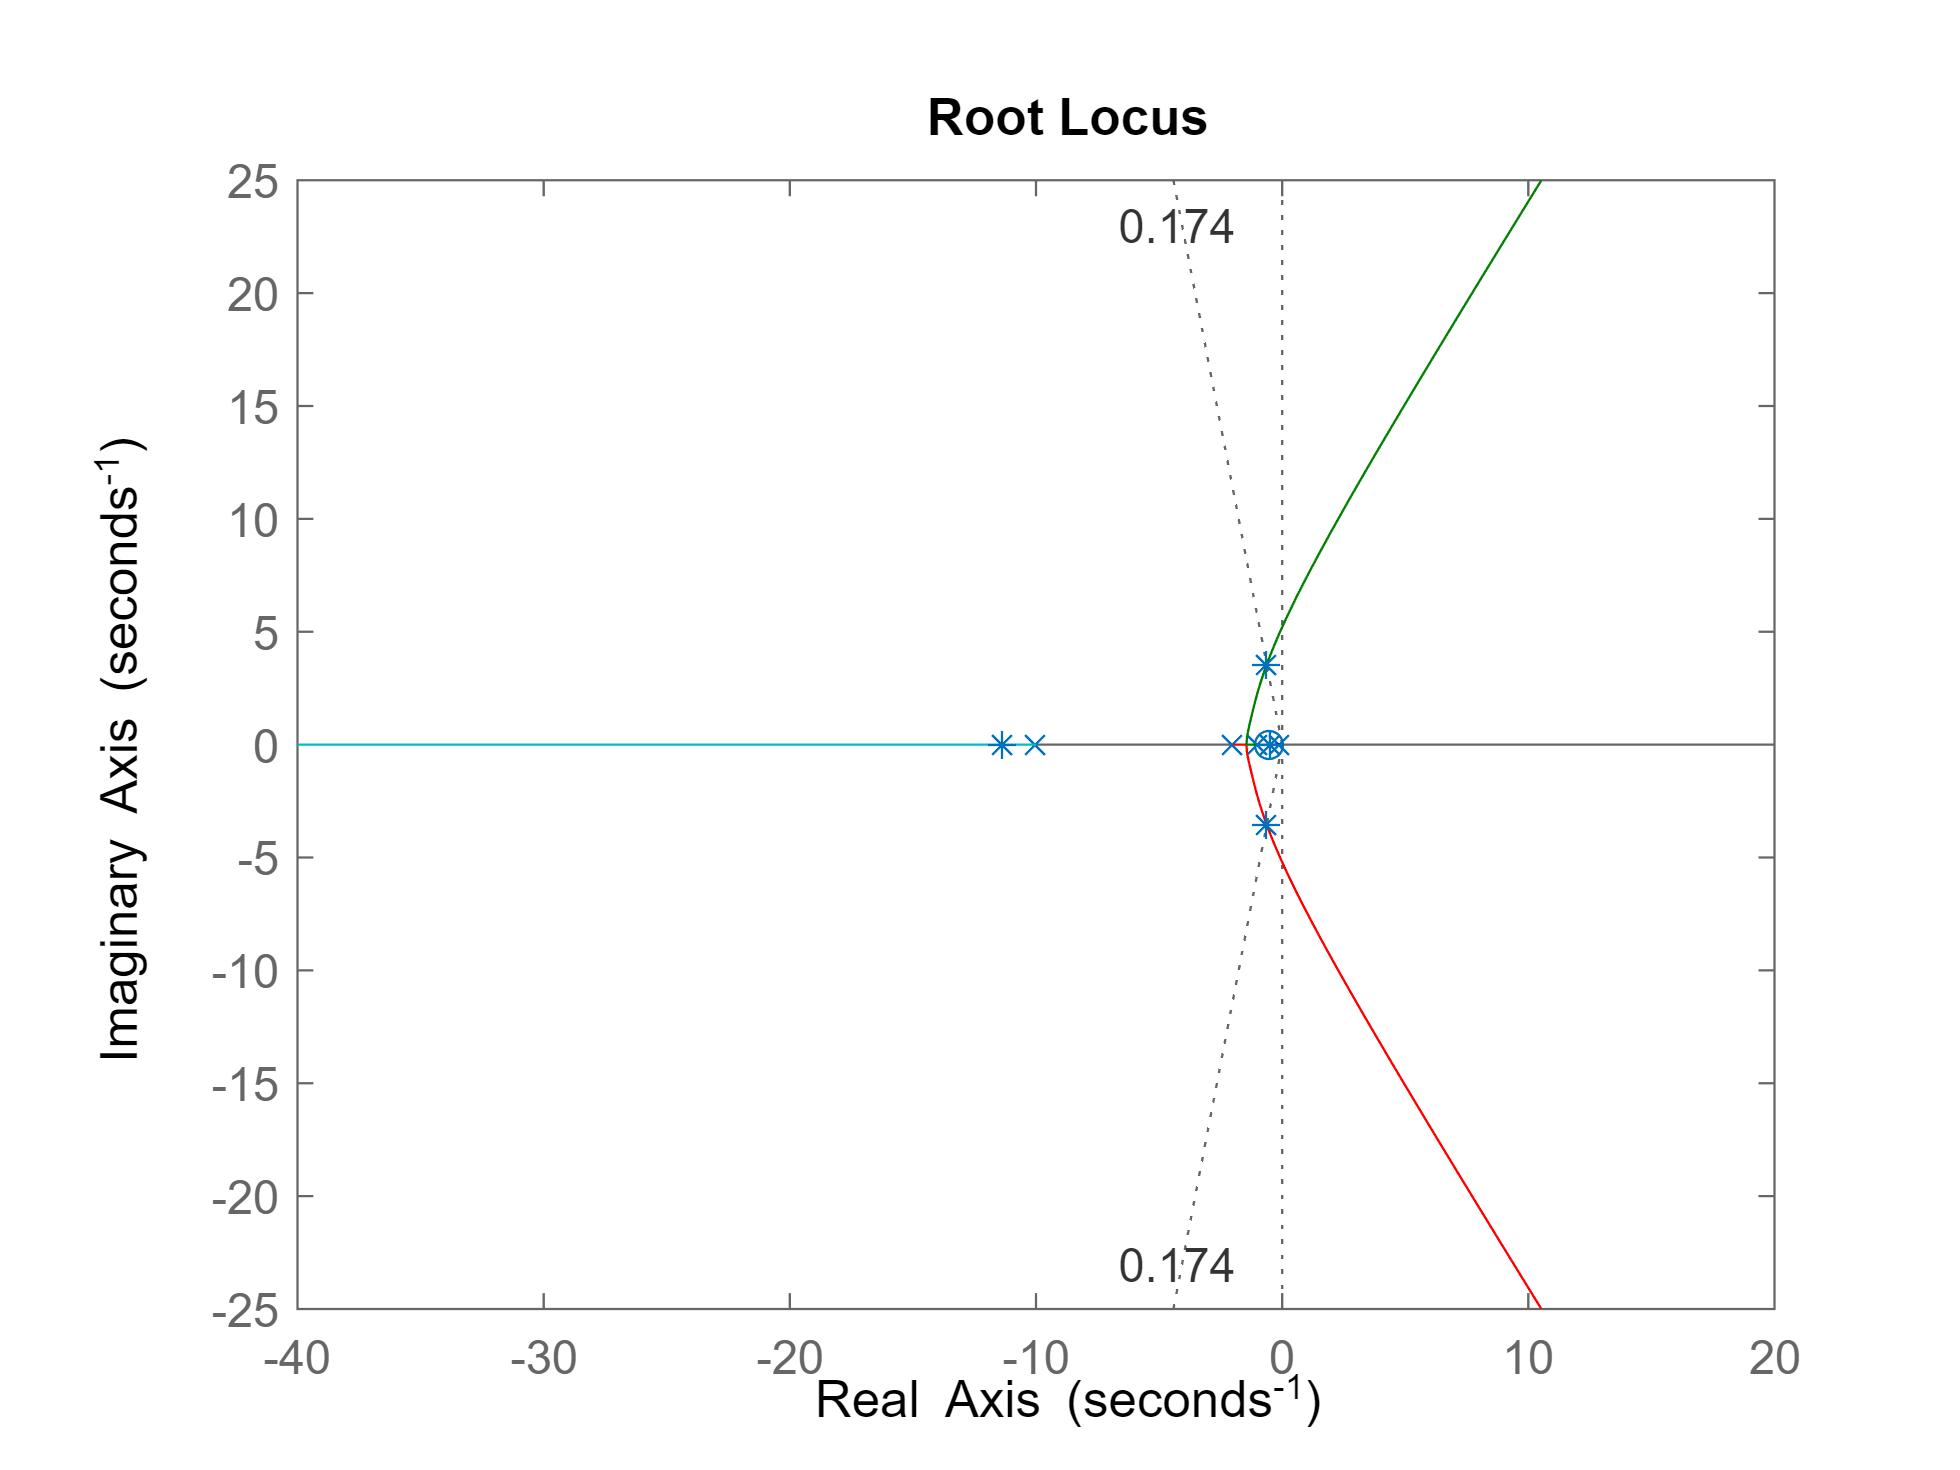

Current plot released


plot(p,'*')
hold


%hold
step(Gcl4)
hold

Current plot held


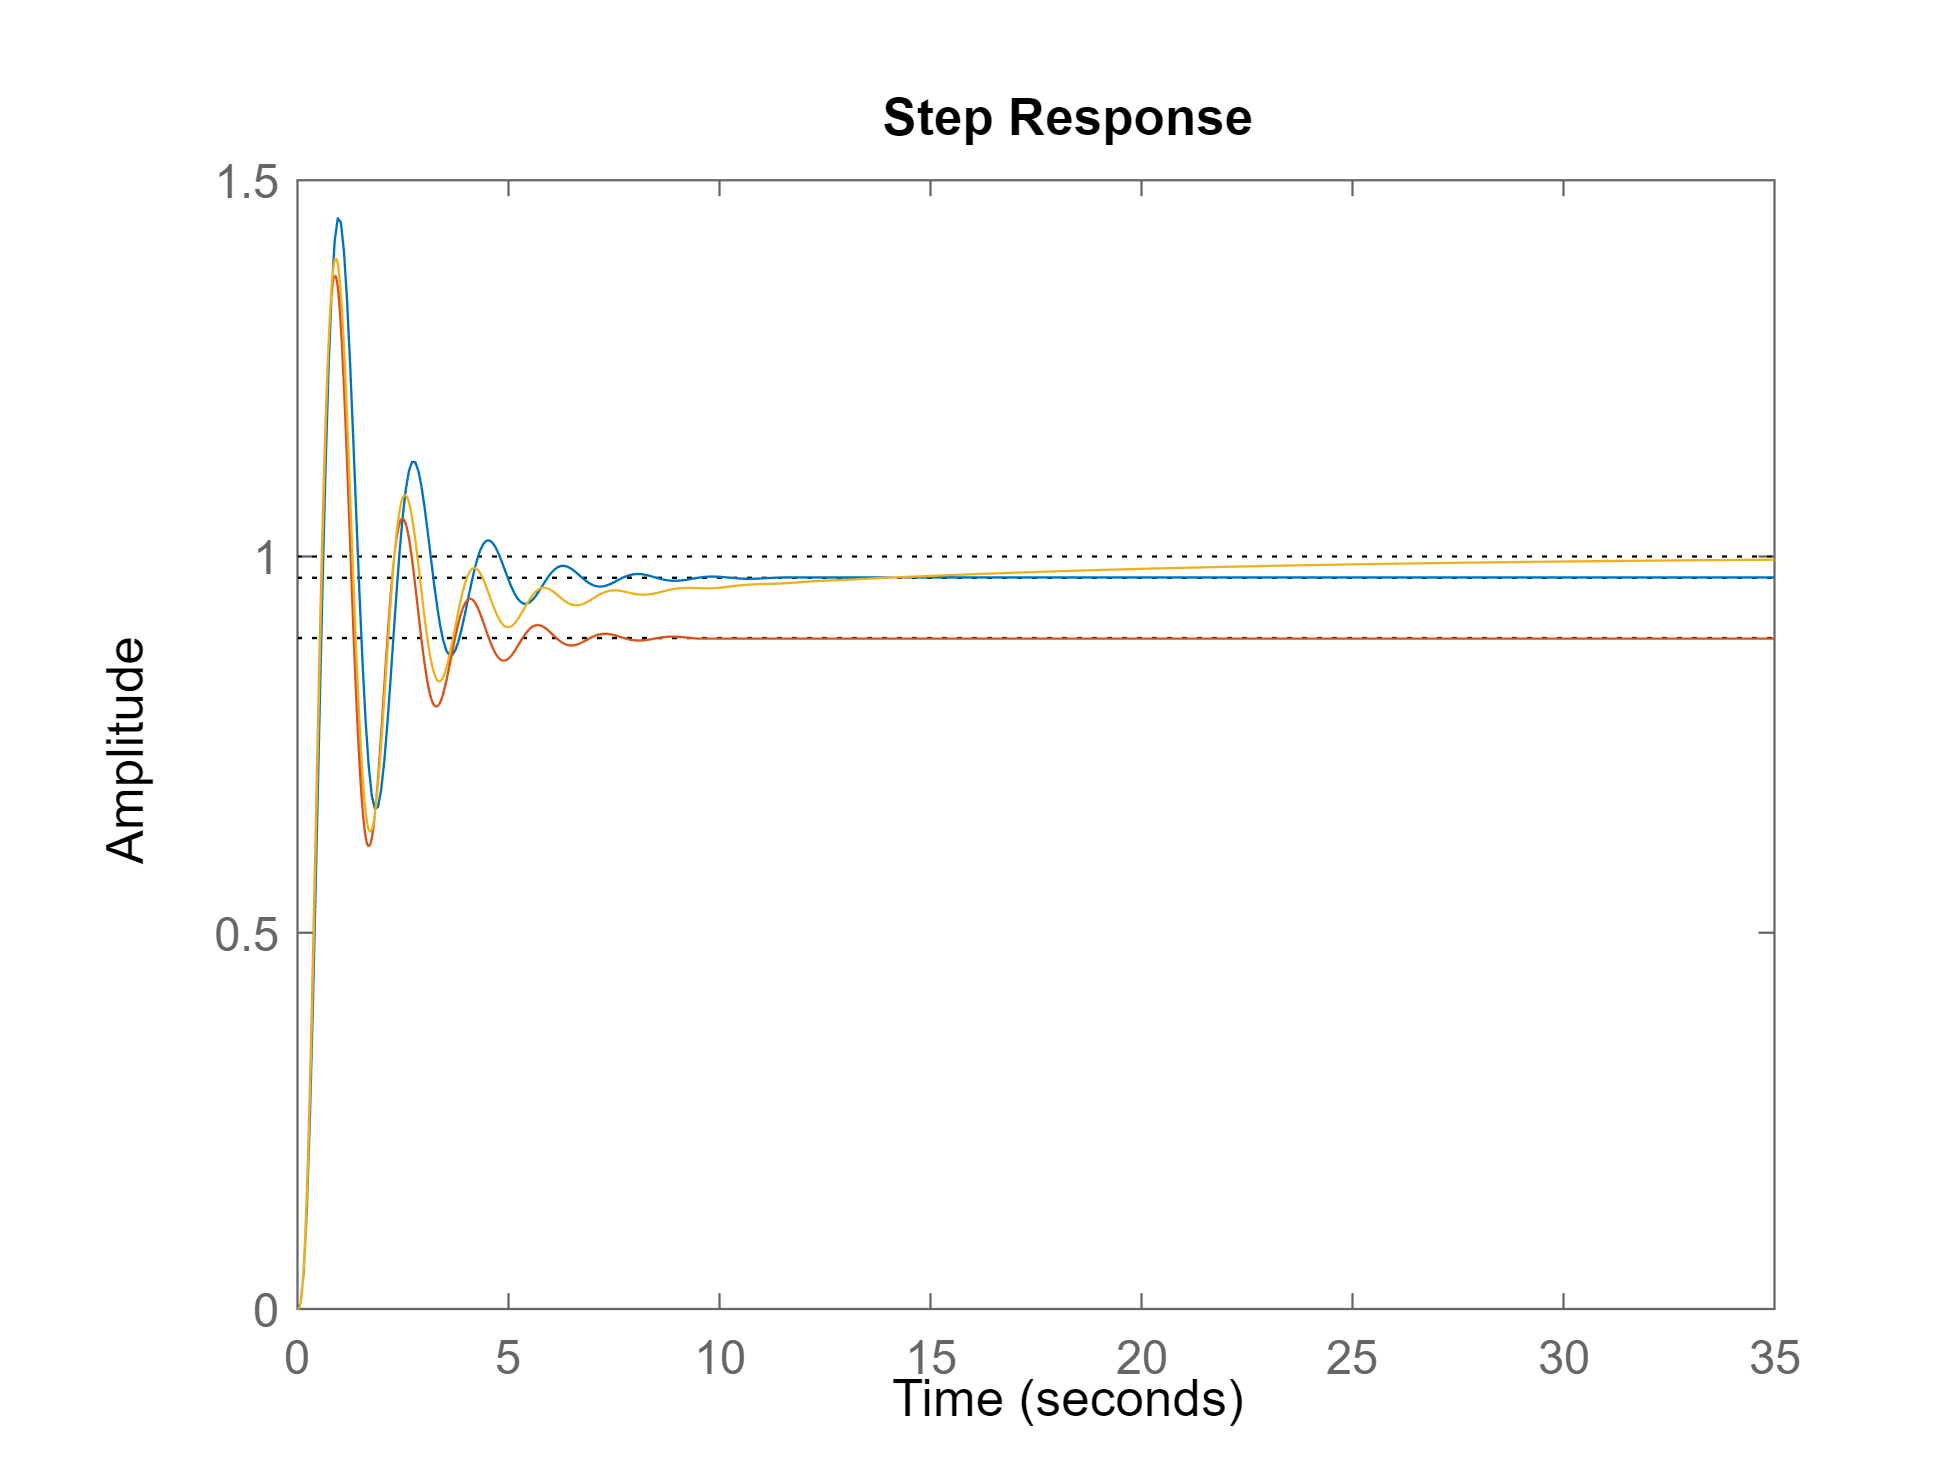

Current plot released


step(Gcl)
step(Gcl3)
hold

### Improving Transient Response via Compensation

#### Ideal Derivative Compensation

For system below, design PD controller to yield 16%

overshoot, and a threefold reduction in settling time.

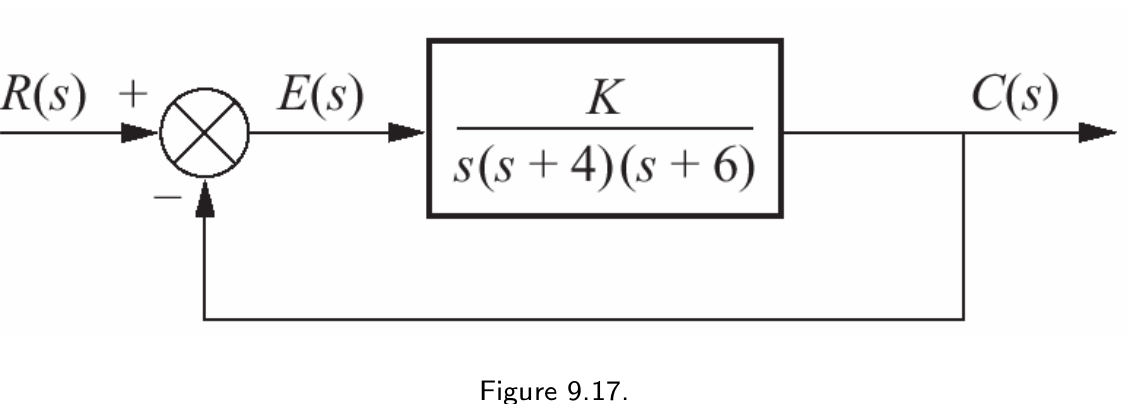

For 16% overshoot

G=zpk([],[0 -4 -6],1)
pos=16
zeta=-log(pos/100)/sqrt(pi^2+log(pos/100)^2)
s_1=-1.205+j*2.064
K=1/abs(evalfr(G,s_1))

Settling time approximately given by $T_s=\frac {4}{\zeta\omega_n}$

Recall though that $\zeta\omega_n$ is just the absolute value of the real part of the the dominant poles

Ts=4/abs(real(s_1))
Gcl=feedback(K*G,1)
pole(Gcl)

3rd pole for the closed loop system is more than 5 times farther left from the $j\omega$-axis than the dominant 2nd order poles so 2nd order approximation should be valid.

 Let $s_1=-\sigma_1\pm j\omega_1=-1.205\pm j 2.064$ be the current pole location for a proportional controller with $K=43.35$.

    Let $s_d=-\sigma_d\pm j\omega_d$ be the new, desired pole location.

    We want the new settling time $T_s^{\textit{new}}$ to be $\frac{1}{3}$ of its current value $T_s$ while still having the same % overshoot. So we want to stay on the same $\zeta$damping ratio line but have the real part of the desired location be 3 times larger since 

$T_s^\textit{new}\approx\frac{4}{\sigma_d}=\frac{T_s}{3}=\frac{1}{3}\times\frac{4}{\sigma_1}$ so $\sigma_d=3\sigma_1=3\times 1.205=3.615$

To keep on the same damping ratio line we must keep the ratio of $\frac{\omega_d}{\sigma_d}$ the same so we also have $\omega_d=3\times\omega_1=3\times 2.064 =6.192$

Thus the new desired pole location is 3 times faster with same %overshoot so

s_d=3*s_1
rlocus(G)
sgrid(zeta,0)
hold
plot(s_1,'*')
plot(s_d,'*')
hold

What we want to do is put a new zero in the system at $s=-\sigma$ via a PD compensator $C(s)=K(s+\sigma)$ such that for some value of $K$ $s_d=-3.6150 + j 6.1920$lies on the root locus:

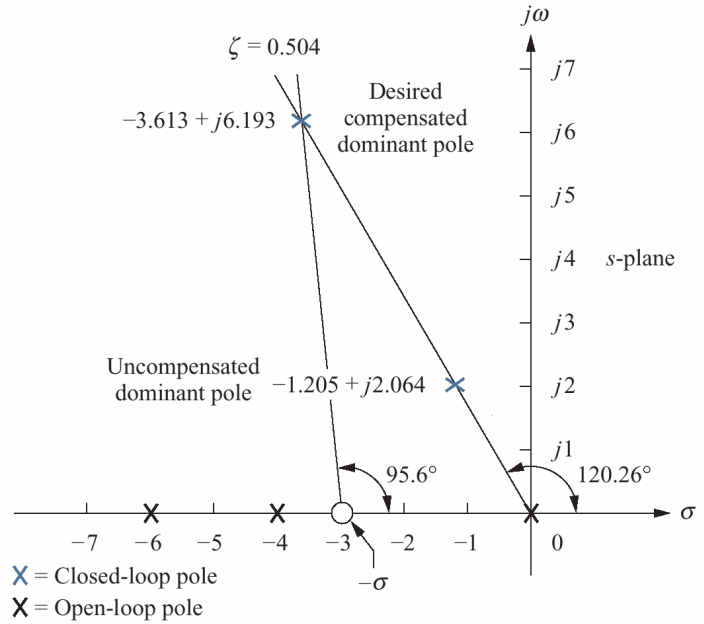

So we see that we must have that


$$\angle(s_d+\sigma)+\angle G(s_d)=(2k+1)\pi, \textrm{ for some }k\\
\angle(s_d+\sigma)=(2k+1)\pi-\angle G(s_d)$$


We can get the vaue of $\angle G(s_d)$ as:


$$G(s)=\frac{1}{s(s+4)(s+6)}\\
G(-3.615 + j6.192) =\frac{1}{(-3.615 + j6.192)(-0.385 + j6.192)(-2.385+ j6.1920)}\\
\ \ \ \ =0.3338 + j3.3715\\
\angle G(-3.615 + j6.192)=\tan^-1\left(\frac{3.3715}{0.3338}\right )=1.4721 \textrm{ rad}$$


 Gats_dAngle=angle(evalfr(G, s_d))

Or in degrees:

 Gats_dAngle*180/pi
 

Thus if we try $k=1$ and substitute $s_d=-3.6150 + j6.1920$ into 


$$\angle(s_d+\sigma)+\angle G(s_d)=(2k+1)\pi, \textrm{ for some }k\\
\angle(s_d+\sigma)=(2k+1)\pi-\angle G(s_d)\\
\angle(s_d+\sigma)=\pi- 1.4721\\
\ \ \ \ \ \ \ \ = 1.6695$$


zeros_dAngle=pi-Gats_dAngle

in radians or in degrees:

(pi-Gats_dAngle)*180/pi

From the above diagram we see that 


$$\tan(\pi-\angle(s_d+\sigma))=\frac{\omega_d}{\sigma_d-\sigma}\\
\sigma_d-\sigma=\frac{\omega_d}{\tan(\pi-\angle(s_d+\sigma))}\\
\sigma=\sigma_d-\frac{\omega_d}{\tan(\pi-\angle(s_d+\sigma))}\\$$


sigma=-real(s_d)-imag(s_d)/tan(pi-zeros_dAngle)

check:

angle(s_d+sigma)+Gats_dAngle

Now we can find the gain $K$for the PD compensator with $G$ to hit desired pole location $s_d=-3.613+j6.192$ as a closed loop pole:

K=1/abs(evalfr((s+sigma)*G,s_d))
GclPD=feedback(K*(s+sigma)*G,1)
step(Gcl)
hold
step(GclPD)
hold

#### Lead controller to improve transient reponse

G=zpk([],[0 -4 -6],1)
s_d

Same desired pole location $s_d$ but we want to achive it with a lead compensator

# 
$$C(s)=K\left(\frac{s+z_c}{s+p_c}\right)$$


We want 


$$1+K\left(\frac{s_d+z_c}{s_d+p_c}\right)G(s_d)=0\\
\angle (s_d+z_c)-\angle(s_d+p_c)+\angle(G(s_d))=(2k+1)\pi\\
\angle (s_d+z_c)-\angle(s_d+p_c)=(2k+1)\pi-\angle(G(s_d))\\
$$


Cangle=pi-angle(evalfr(G,s_d))
Cangle*180/pi

Since the required lead/lag controller angle required is more than $90^\circ$ the controller zero at $-z_c$ has to be to the right of the desired pole location real part $-\sigma_d$, i.e., $-\sigma_d <-z_c$ so $\sigma_d>z_c$

Try $z_c=2.1$ then $\angle(s_d+z_c)$ is

z_c=2.1
Zangle=angle(evalfr(s+z_c,s_d))

Pangle=Zangle-Cangle


$$\tan(s+p_c)=\frac{\omega_d}{p_c-\sigma_d}\\
p_c-\sigma_d=\frac{\sigma_d}{\tan(s+p_c)}\\
p_c=\frac{\sigma_d}{\tan(s+p_c)}+\sigma_d$$


Note that $s_d=-\sigma_d\pm j\omega_d$ so $\sigma_d=- real(s_d)$

p_c=imag(s_d)/tan(Pangle)-real(s_d)
K=1/abs(evalfr((s+z_c)/(s+p_c)*G,s_d))
Gcl3=feedback(K*(s+z_c)/(s+p_c)*G,1)
step(Gcl3)
hold
step(Gcl)
step(GclPD)
hold
pole(Gcl3)

This controller is not producing the same overshoot since the zero at -2.1 and closed loop pole at -1.7257 are not effectively cancelling.

Also note that the gain of this controller is much larger:

K

This can be a problem for PD controllers since if there is any sensor noice it gets amplified by the derivative operator.

### PID Controller Design Example

Design PID controller so system has 20% overshoot, zero steady state error for step input, and peak time that is 2/3 that of original system.

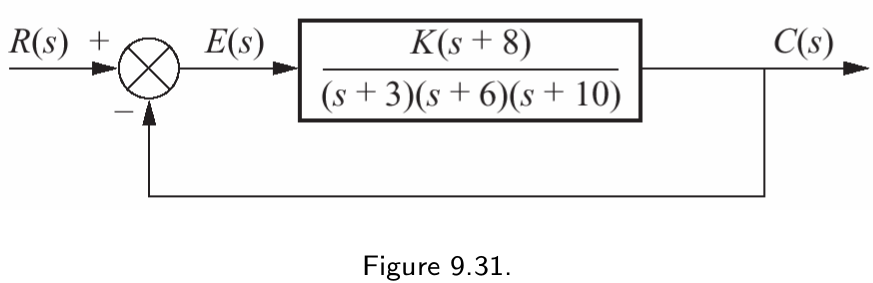

G=zpk([-8],[-3 -6 -10],1)
pos=20
zeta=-log(pos/100)/sqrt(pi^2+log(pos/100)^2)
rlocus(G)
sgrid(zeta,0)
s_1=-5.415+j*10.57
hold
plot(s_1,'*')
hold
K=1/abs(evalfr(G,s_1))
Gcl=feedback(K*G,1)
pole(Gcl)
step(Gcl)

In this case we would expect the peak time for the 2nd order system to be:


$$T_p\approx \frac{\pi}{\omega_1}=\frac{\pi}{10.57}=0.297$$


for the current 2nd order pole position $s_1=-\sigma_1\pm j\omega_1=-5.415 \pm j10.57$

For a new desired pole location $s_d=-\sigma_d\pm j \omega_d$ we want 


$$\omega_d=\frac{3}{2} \times\frac{\pi}{T_p^\textit{old}}\\
\ \ \ =\frac{3}{2} \times\frac{\pi}{0.297}\\
\ \ \ =15.87$$


or equivalently:


$$T_p=\frac{\pi}{\omega_d}=\frac{2}{3} \times T_p^\textit{old}=\frac{2}{3}\times\frac{\pi}{\omega_1}\\
\omega_d=\frac{3}{2}\times\omega_1\\
\ \ \ =\frac{3}{2}(10.57)=15.87$$


If we want to keep the damping ration the same, then we need to increase the value of real part of the desired pole by the same amount, i.e., $\sigma_d=\frac{3}{2}\sigma_1=\frac{3}{2}(4.415)=8.13$

s_d=3/2*s_1
 Gats_dAngle=angle(evalfr(G, s_d))

Or in degrees:

 Gats_dAngle*180/pi
 

Thus if we try $k=1$ and substitute $s_d=-8.1225 + j15.855$ into 


$$\angle(s_d+\sigma)+\angle G(s_d)=(2k+1)\pi, \textrm{ for some }k\\
\angle(s_d+\sigma)=(2k+1)\pi-\angle G(s_d)\\
\angle(s_d+\sigma)=\pi- 1.4721\\
\ \ \ \ \ \ \ \ = 1.6695$$


zeros_dAngle=pi-Gats_dAngle

From the above diagram we see that 


$$\tan(\pi-\angle(s_d+\sigma))=\frac{\omega_d}{\sigma_d-\sigma}\\
\sigma_d-\sigma=\frac{\omega_d}{\tan(\pi-\angle(s_d+\sigma))}\\
\sigma=\sigma_d-\frac{\omega_d}{\tan(\pi-\angle(s_d+\sigma))}\\$$


sigma=-real(s_d)-imag(s_d)/tan(pi-zeros_dAngle)

check:

angle(s_d+sigma)+Gats_dAngle

Now we can find the gain $K$for the PD compensator with $G$ to hit desired pole location $s_d=-8.13+j15.87$ as a closed loop pole:

s=tf('s')
K=1/abs(evalfr((s+sigma)*G,s_d))
GclPD=feedback(K*(s+sigma)*G,1)
step(Gcl)
hold
step(GclPD)
hold

Now add a PI controller $C_\textit{PI}(s)=\frac{(s+0.5)}{s}$ to our PD compensator (controller) $C_\textit{PD}(s)=(s+55.92)$ to get the PID controller:


$$C_\textit{PID}(s)=C_\textit{PD}(s) C_\textit{PI}(s)\\
\ \ \ \ \ \ = \frac{K(s+55.92)(s+0.5)}{s}$$


rlocus((s+sigma)*(s+0.5)/s*G)
sgrid(zeta,0)
s_pid=-7.516+j*14.67
hold
plot(s_pid,'*')
hold
K_3=1/abs(evalfr((s+sigma)*(s+0.5)/s*G,s_pid))
GclPID=feedback(K_3*(s+sigma)*(s+0.5)/s*G,1)
step(Gcl)
hold
step(GclPD)
step(GclPID)
hold
pole(GclPID)